# 034IN -FONDAMENTI DI AUTOMATICA - FUNDAMENTALS OF AUTOMATIC CONTROL 

# FULL WRITTEN EXAMINATION -  A.Y. 2023/2024

**September 2, 2024**

# PART 2 - Design of a Controller

## Control of the Temperature in a Chemical Reactor

### First Approach: a Dual-Loop Scheme

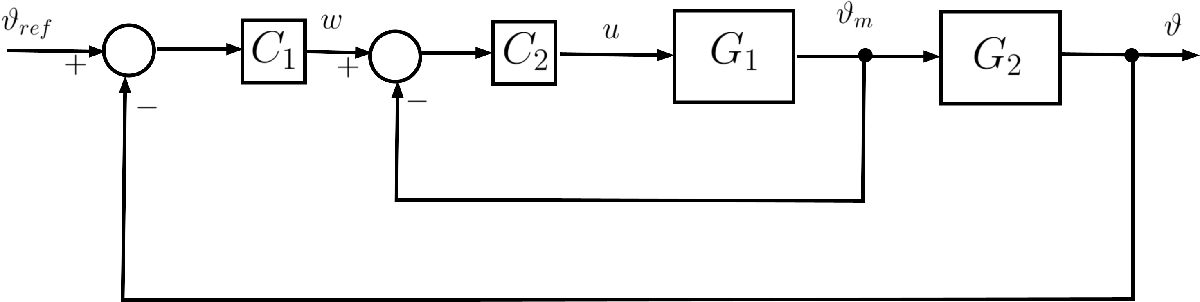

Figure 1: dual-loop control scheme for the temperature control in a chemical reactor.

To control the temperature $\vartheta(t)$ in a chemical reactor, the control system in Figure 1 is used, where $\vartheta_{\text{ref}}(t)$ is the reference temperature (the desired temperature). The temperatures $\vartheta(t)$ and $\vartheta_m(t)$in the reactor and in the cooler, respectively, are measurable and can be used to control the valve $u(t)$. 

- The **inner** **loop** regulates the cooler's temperature, $\vartheta_m(t)$, using $w(t)$ as the reference target. 

- The inner loop control variable is the cooling valve position $u(t)$. 

- The **outer** **loop** aims to regulate the temperature $\vartheta(t)$ of the fluid in the reactor, with $\vartheta_{\text{ref}}(t)$ as the reference temperature. 

- The control variable $w(t)$ is acting as the reference for the inner control loop.

It is here assumed that both $C_1(s)$ and $C_2(s)$ are proportional controllers:


$$C_1(s) = k_1\;,\qquad C_2(s) = k_2\;,\qquad k_1\,,\;k_2 \in \mathbb{R}$$


Finally


$$G_1(s) = \frac{1}{10\,s+1} \;, \qquad G_2(s) = \frac{1}{\left(30\,s+1\right)\, \left( 3\,s+1\right)}$$


### Assignment 		

**A1**: Let $k_2 = +19$ and carry out the following steps:

- Compute the transfer function from $w(t)$ to $\vartheta_m(t)$. Let identify such a transfer function as $F_2(s)$.

- Draw the Bode plot (both the asymptotic and the effective) of the frequency response of $F_2(s)$.

- Compare the Bode plots of $F_2(j \omega)$ with those of $G_2(j \omega)$. Any remark?

- Choose the gain $k_1$ so that the gain margin (of the outer open-loop transfer function) results $K_{m\,1}=12\,\text{dB}$.

- Determine the crossover frequency $\omega_{c\,1}$, the phase margin $\varphi_{m\,1}$, and the steady-state error, assuming that the temperature reference is a stepwise function:  $\vartheta_{\text{ref}}(t) = \mathbf{1}(t)$

As usual, $\mathbf{1}(t)$ denotes the unit step function: $\mathbf{1}(\tau) = \left\{ \begin{array}{rcl}
0 &\longleftrightarrow& \tau <0 \\
1 &\longleftrightarrow& \tau \ge 1
\end{array} \right.$ 

**HINT**: in order to fulfil assignment A1.4 follow this approach

- Firstly determine the angular frequency $\omega_{\pi}$, such that $\arg \left[ F_2(j \omega_{\pi}) \cdot G_2(j \omega_{\pi})\right] = -180^{\degree}$. It does not depend on the gain $k_1$, doesn’t it?

- Evaluate the amplitude of $L_1(j \omega_{\pi})$, with $L_1(s) = F_2(s) \cdot G_2(s)$, i.e. the outer open-loop transfer function. That amplitude has to depend on the gain $k_1$.

- Determine the proper value for the gain $k_1$, in order to guarantee the gain margin $K_{m\,1}=12\,\text{dB}$.

### Second Approach: a Single-Loop Scheme

Consider now the following control system scheme, with a simple feedback loop.:

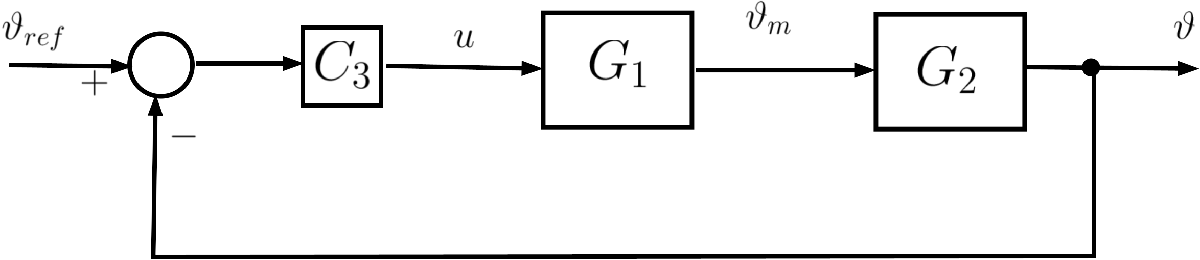

Figure 2: a simple feedback loop for the temperature control in the chemical reactor.

The controller $C_3(s)$ is a simple proportional controller 


$$C_3(s) = k_3\;,\quad k_3 \in \mathbb{R}$$


and


$$G_1(s) = \frac{1}{10\,s+1} \;, \qquad G_2(s) = \frac{1}{\left(30\,s+1\right)\, \left( 3\,s+1\right)}$$


As in the previous scenario, $\vartheta_{\text{ref}}(t)$ is the reference temperature (the desired temperature). The variables $\vartheta(t)$ and $\vartheta_m(t)$ are the temperatures in the reactor and in the cooler, respectively. The variable $u(t)$ is the position of the cooling valve. 

### Assignment 		

**A2**: Carry out the following steps:

- Compute the open-loop transfer function and identify such a transfer function as $\hat{L}(s)$.

- How is the Bode plot affected? Draw the Bode plot (both the asymptotic and the effective) of the frequency response of $\hat{L}(s)$.

- Compare the Bode plots of $\hat{L}(j \omega)$ with those obtained, in the previous scenario, for the outer loop open-loop transfer function, i.e. $L_1(j \omega) = F_2(j \omega) \cdot G_2(j \omega)$. Any remark?

- Choose the gain $k_3
$ so that the gain margin results $\hat K_{m}=12\,\text{dB}$.

- Determine the crossover frequency $\hat \omega_{c}$, the phase margin $\hat \varphi_{m}$, and the steady-state error, assuming that the temperature reference is a stepwise function:  $\vartheta_{\text{ref}}(t) = \mathbf{1}(t)$.

- **Compare** with the results in the scenario A1. **Conclusions**?

As usual, $\mathbf{1}(t)$ denotes the unit step function: $\mathbf{1}(\tau) = \left\{ \begin{array}{rcl}
0 &\longleftrightarrow& \tau <0 \\
1 &\longleftrightarrow& \tau \ge 1
\end{array} \right.$ 

## Foreword to the Provided Solution

The live script is very long. In fact, we propose two different approaches to fulfil the request for a few parts of the solution. Moreover, we insert some more plots than the ones required to better clarify the solution approach.

### A Practical Advise 	

Due to the length of the script, the suggested practical approach is to analyse and execute the code section by section, using the commands `"Run Section"` or `"Run and Advance"`.

## Solution 

### First Approach: a Dual-Loop Scheme

% --- Live Script Initialisation ---
clear
close all
clc


% adding folders (and subfolders) to search path
addpath(genpath('BodeDiagram/'))

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams


### A1: Design of the Outer Loop Controller 

Let's define the transfer function of the processes $G_1(s)$, $G_2(s)$ and configure the MATLAB Search Path, by adding the folder containing the M-code able to compute and plot the asymptotic approximation of the Bode diagrams of the frequency response of a given transfer function. Finally, let's assign the inner-loop controller, as required in A1.1.

% let's define the transfer function builder element
s=tf('s');


% --- the process transfer functions G1s & G2s ---
G1s = 1/(10*s+1);           % the process G1(s)
G2s = 1/((30*s+1)*(3*s+1)); % the process G2(s)


#### **A1.1 - The Inner Loop Controller: A Simple Proportional Gain**

% --- the inner loop controller C2s ---
K2 = +19; 
C2s = tf(K2);


#### The Inner-Loop Complementary Sensitivity Function

As requested in A1.1, let's compute the closed-loop transfer function $F_2(s)$ of the inner loop

% let's compute the open-loop TF of the inner loop L2s
L2s = C2s*G1s;    % the open-loop TF

F2s = feedback(L2s, 1, -1)


F2s =
 
     19
  ---------
  10 s + 20
 
Continuous-time transfer function.
Model Properties


#### **A1.3 - **Comparing the Bode Plots

As requested in A1.1, let's compare the Bode plots of $F_2(j \omega)$ and $G_2(j \omega)$:

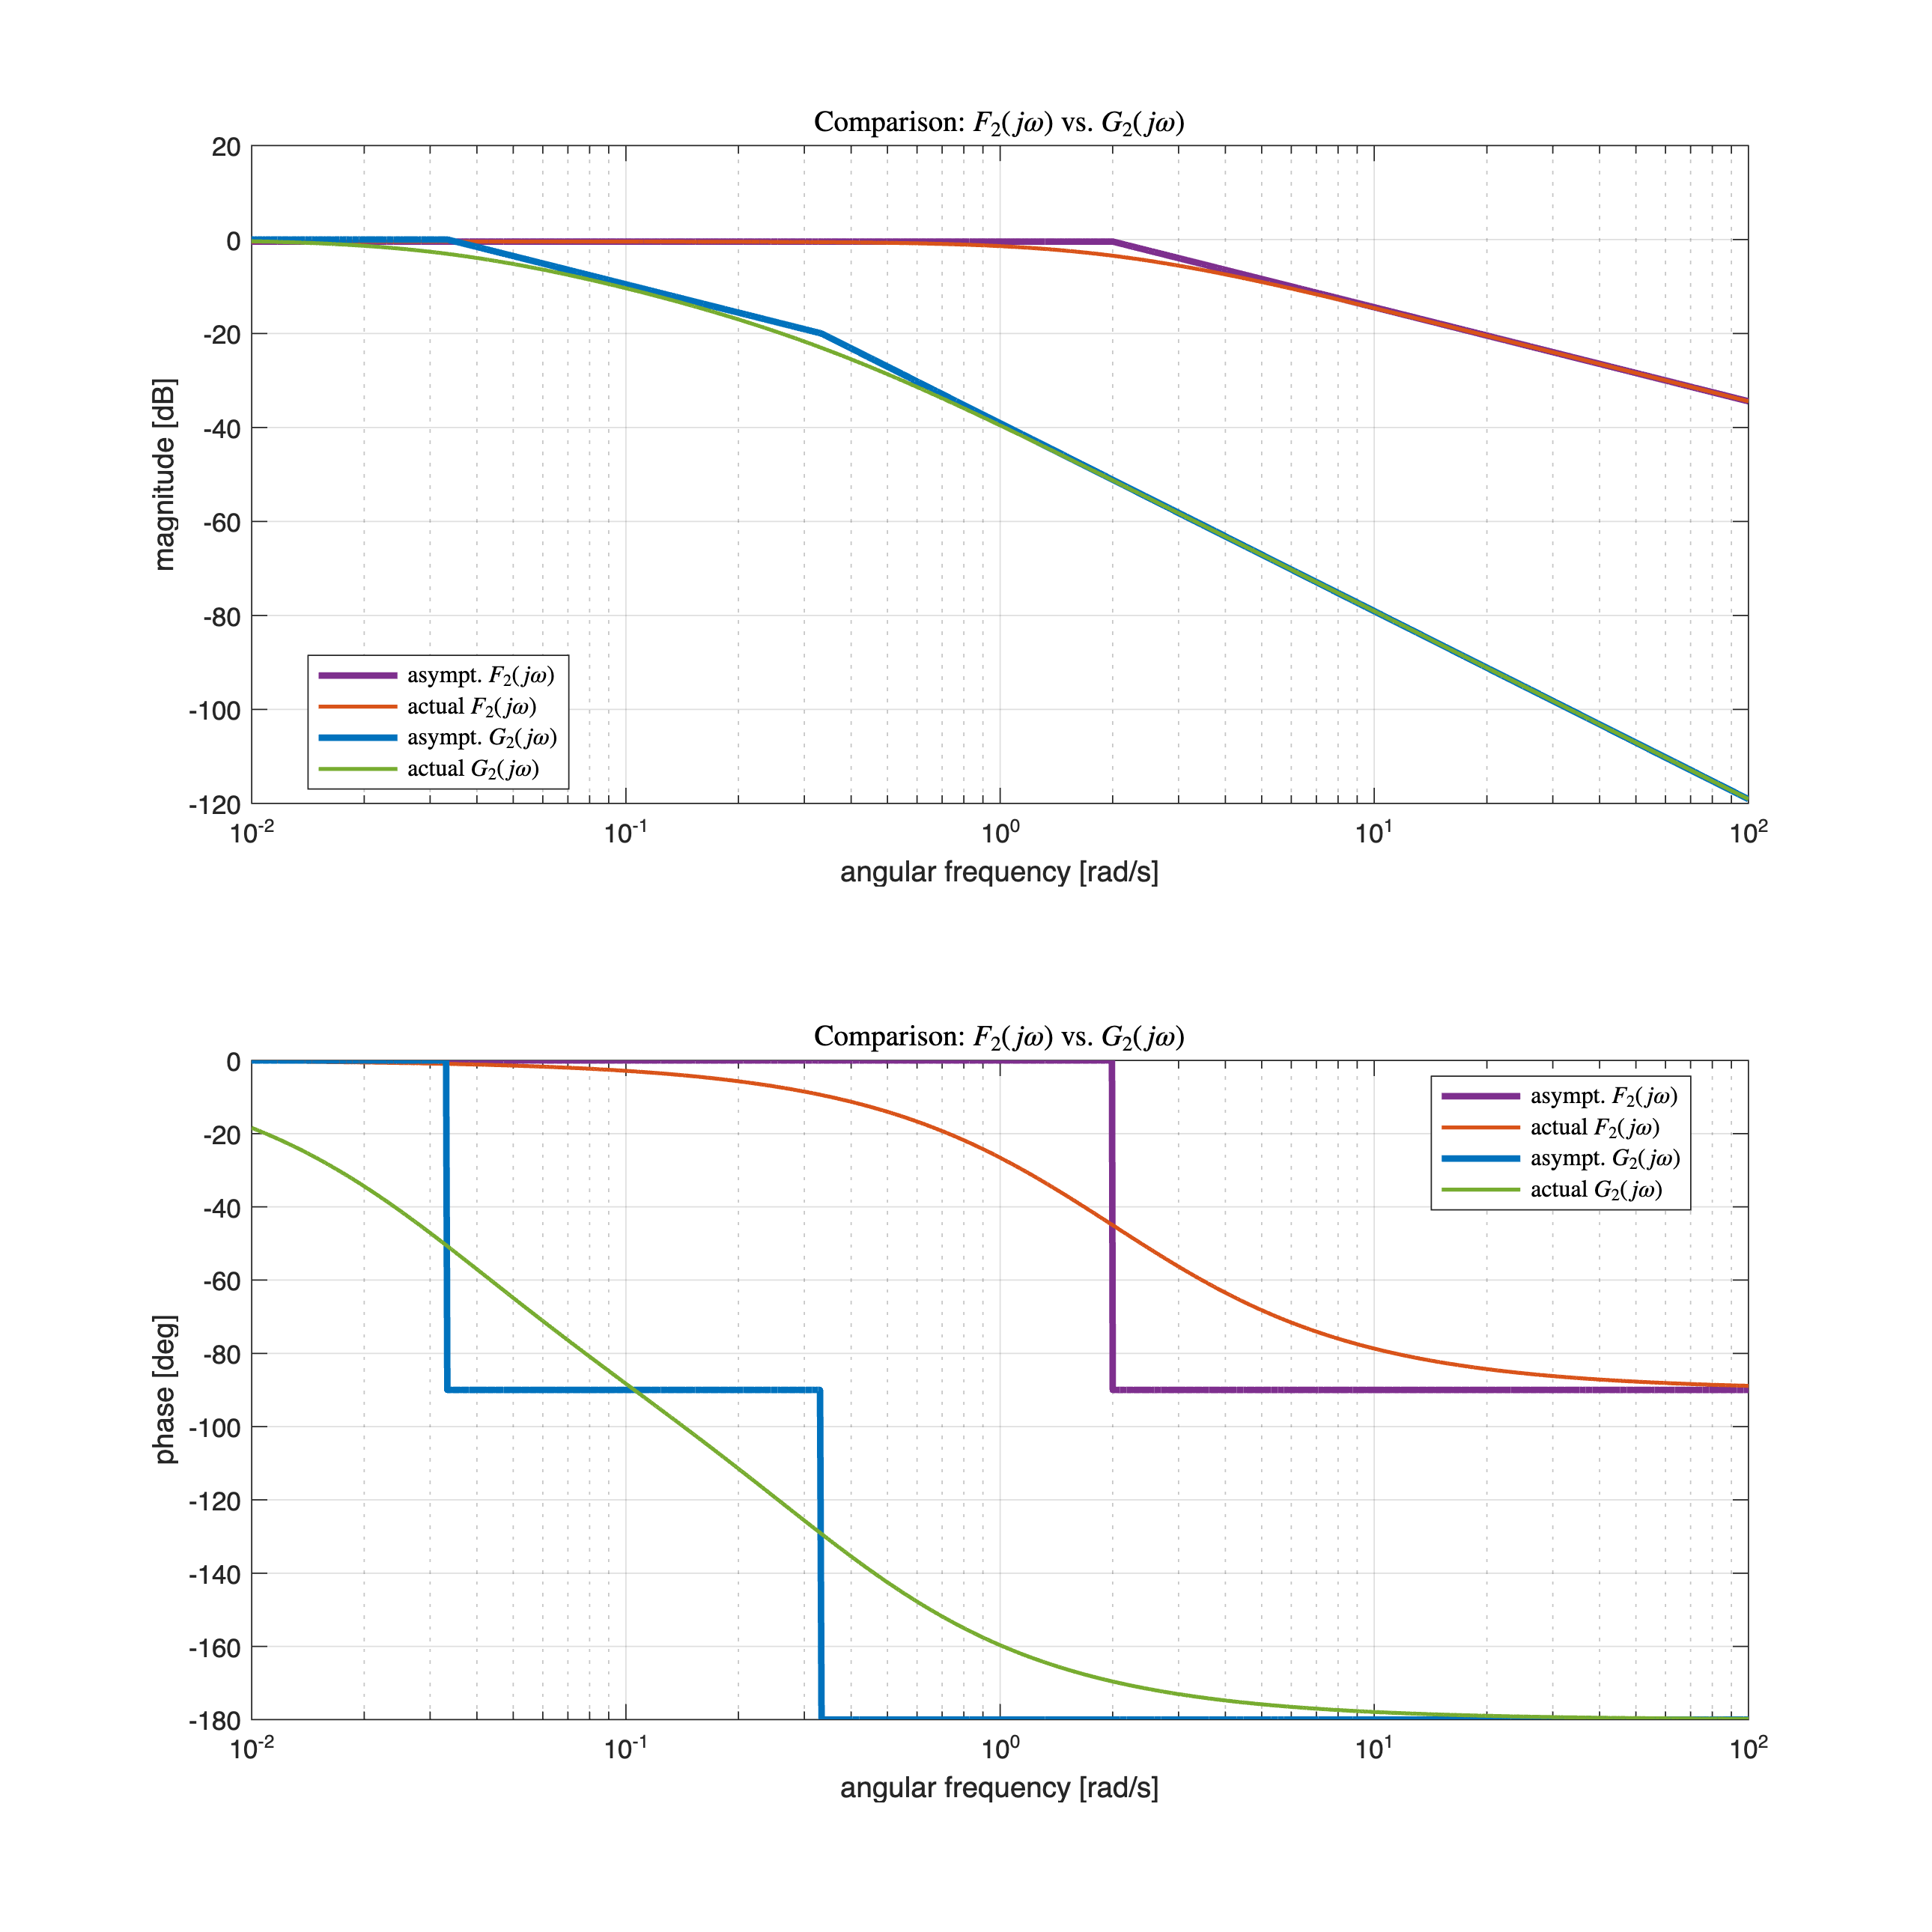

% --- A1.1: F2(j omega) vs G2(j omega) ---
hf1 = figure('Units','centimeters', 'Position',[0.1,0.1, 26, 26]);


omVALS = logspace(-2, 2, 1e5); % ang. freqs in [1/100; 100]
[hax1, hax2] = drawBodediagrams(F2s, omVALS, Bcolors(3, :), 2.5, '-', ...
                       Bcolors(6, :), 1.5, '-', hf1); % assignment A1.2

drawBodediagrams(G2s, omVALS, Bcolors(1, :), 2.5, '-', ...
                       Bcolors(4, :), 1.5, '-', hf1);

title(hax1, 'Comparison: $F_2(j \omega)$ vs. $G_2(j \omega)$', 'Interpreter', 'latex');
title(hax2, 'Comparison: $F_2(j \omega)$ vs. $G_2(j \omega)$', 'Interpreter', 'latex');

legend(hax1,  'asympt. $F_2(j \omega)$', 'actual $F_2(j \omega)$', ...
             'asympt. $G_2(j \omega)$', 'actual $G_2(j \omega)$','Location', 'best', ...
             'Interpreter', 'latex');
legend(hax2,   'asympt. $F_2(j \omega)$', 'actual $F_2(j \omega)$', ...
             'asympt. $G_2(j \omega)$', 'actual $G_2(j \omega)$','Location', 'best', ...
             'Interpreter', 'latex');

**Remark**: you can note that

- The crossover frequency $\omega_c$ for $F_2(s)$ is larger than the crossover frequency for $G_2(s)$: this **feature** is **effective** in **keeping** the **design** of the outer loop controller **easy**. You can approximate the transfer function $F_2(s)$ with an algebraic term (the static gain) when considering the frequencies from zero till the crossover frequency of $G_2(s)$.

- Moreover, considering the series connection of $F_2(s)$ and $G_2(s)$, i.e. $L_1(s) = F_2(s) \cdot G_2(s)$, you note that the crossover frequency $\omega_{c\,L_1}$ and the phase margin $\varphi_{m\,L_1}$ are loosely affected by $F_2(s)$, with respect to the crossover frequency and the phase margin obtained whiit $G_2(s)$ only

fare grafici

#### A1.4 - Tuning the Outer-Loop Controller

To properly tune the gain $k_1$ (i.e. the outer loop controller $C_1(s)$ ), let's determine the outer-loop open-loop transfer function $L_1(s)$, i.e.


$$L_1(s) = C_1(s) \cdot F_2(s) \cdot G_2(s) \; \Longrightarrow \; L_1(s) = k_1 \cdot \frac{19}{10\,s+20} \cdot \frac{1}{\left(30\,s+1\right)\, \left( 3\,s+1\right)} = \frac{19 k_1}{\left(10\,s+20 \right) \left(30\,s+1\right)\, \left( 3\,s+1\right)} = 
\frac{\displaystyle \frac{19}{20} k_1}{\left(0.5\,s+1 \right)\left(30\,s+1\right)\, \left( 3\,s+1\right)}$$


As preliminar check, let's draw the Bode plots for $L_1(j \omega)$:

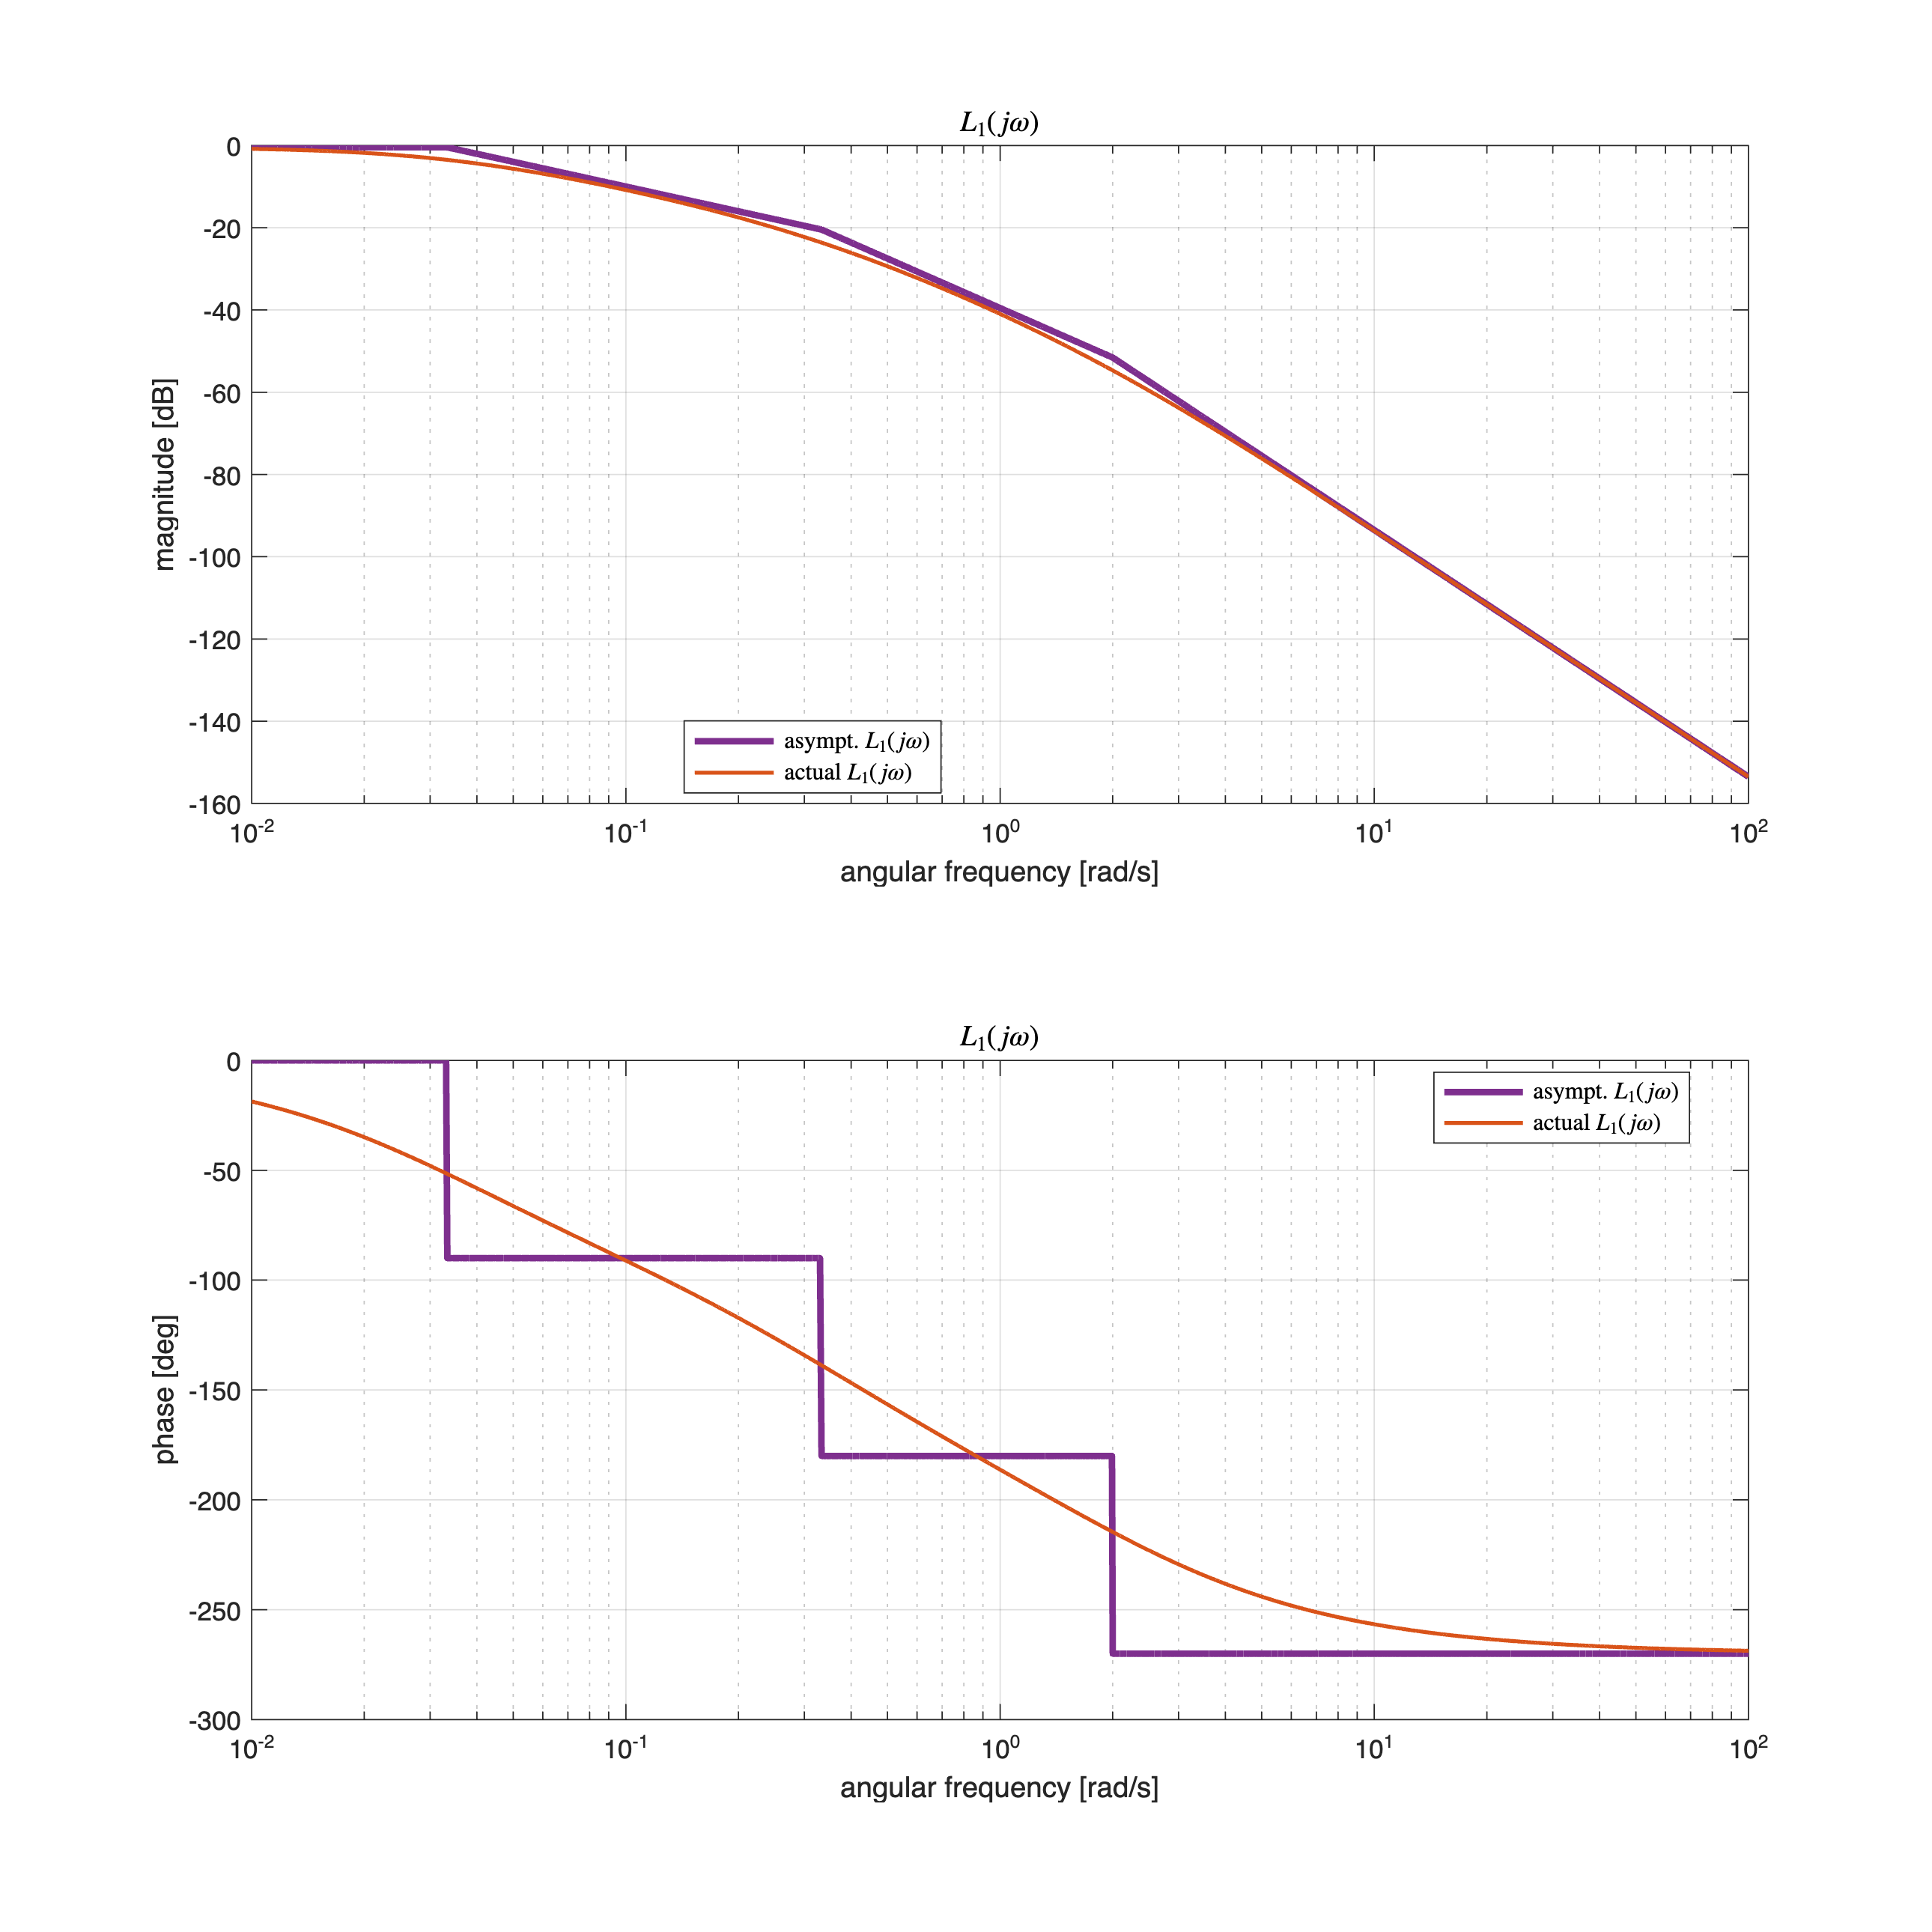

K1 = +1; 
C1s = tf(K1);

L1s = C1s*F2s*G2s;

hf2 = figure('Units','centimeters', 'Position',[0.1,0.1, 26, 26]);


omVALS = logspace(-2, 2, 1e5); % ang. freqs in [1/100; 100]
[hax3, hax4] = drawBodediagrams(L1s, omVALS, Bcolors(3, :), 2.5, '-', ...
                       Bcolors(6, :), 1.5, '-', hf2); % assignment A1.2

title(hax3, '$L_1(j \omega)$', 'Interpreter', 'latex');
title(hax4, '$L_1(j \omega)$', 'Interpreter', 'latex');

legend(hax3,  'asympt. $L_1(j \omega)$', 'actual $L_1(j \omega)$', ...
              'Location', 'best', ...
             'Interpreter', 'latex');
legend(hax4,  'asympt. $L_1(j \omega)$', 'actual $L_1(j \omega)$', ...
              'Location', 'best', ...
             'Interpreter', 'latex');

Analysing the Bode plots, we can assert that the angular frequency $\omega_{\pi}$ exists for sure, and $\omega_{\pi} < 1 \,\text{rad/s}$. How to compute $\omega_{\pi}$?

**First** **approach**: exploiting the Matlab command `margin( )`

[~, ~, omega_pi_approx, ~] = margin(L1s)

omega_pi_approx = 0.8628

rad2deg(angle(freqresp(L1s, omega_pi_approx)))

ans = 179.9994

**Second** **approach**: applying some mathematical manipulations. 

As suggested in A1.4, let's calculate the angular frequency $\omega_{\pi}$as


$$\omega_{\pi}: \arg L_1(\j \omega_{\pi}) = -180^{\degree} \; \Longleftrightarrow \; \arg \left( \frac{19}{20} k_1 \right) - \arg \big[ \left( 0.5\,j \omega_{\pi}+1 \right) \left(  30\,j \omega_{\pi}+1\right) \left( 3\,j \omega_{\pi}+1 \right) \big] = -180^{\degree}$$


Assuming $k_1 >0$, we obtain


$$\omega_{\pi}: \arg L_1(\j \omega_{\pi}) = -180^{\degree} \; \Longleftrightarrow \; - \arg \big[ \left( 0.5\,j \omega_{\pi}+1 \right) \left(  30\,j \omega_{\pi}+1\right) \left( 3\,j \omega_{\pi}+1 \right) \big] = -180^{\degree}$$


Thus


$$\omega_{\pi}: \arg L_1(\j \omega_{\pi}) = -180^{\degree} \; \Longleftrightarrow \;  \arg \big[ \left( 0.5\,j \omega_{\pi}+1 \right) \big] + \arg \big[ \left(  30\,j \omega_{\pi}+1\right)\big] + \arg \big[ \left( 3\,j \omega_{\pi}+1 \right) \big] = 180^{\degree}$$



$$ \arg \big[ \left(  30\,j \omega_{\pi}+1\right)\big] + \arg \big[ \left( 3\,j \omega_{\pi}+1 \right) \big] = 180^{\degree} - \arg \big[ \left( 0.5\,j \omega_{\pi}+1 \right) \big] $$


Since $\omega_{\pi} >0$


$$\arctan \left( \frac{30 \omega_{\pi} }{1}\right) + \arctan \left( \frac{3 \omega_{\pi} }{1}\right) = 
180^{\degree} - \arctan \left( \frac{0.5 \omega_{\pi} }{1}\right) \; \Longleftrightarrow \; 
\arctan \left(30 \omega_{\pi} \right) + \arctan \left(3 \omega_{\pi}\right) = 
180^{\degree} - \arctan \left(0.5 \omega_{\pi}\right)$$


Given the trigonometric identities


$$\tan \left( \alpha+\beta \right) = \frac{\tan (\alpha) + \tan( \beta)}{1-\tan (\alpha) \tan (\beta)} \quad
\alpha+\beta \neq 90^{\degree} + n 180^{\degree}\,,\; n \in \mathbb{Z}$$


and


$$\tan \left(180^{\degree} - \delta \right) = - \tan \delta$$


we obtain


$$\arctan \left(30 \omega_{\pi} \right) + \arctan \left(3 \omega_{\pi}\right) = 
180^{\degree} - \arctan \left(0.5 \omega_{\pi}\right) \; \Longleftrightarrow \;
\frac{33\omega_{\pi}}{1-90\omega_{\pi}^2} = - 0.5 \omega_{\pi}$$


Assume


$$\omega_{\pi} \neq 0\;,\quad 1-90 \omega_{\pi}^2 \neq 0\;,\quad \omega_{\pi}>0$$


So 


$$\frac{33\omega_{\pi}}{1-90\omega_{\pi}^2} = - 0.5 \omega_{\pi} \; \Longleftrightarrow \;
\frac{33}{1-90\omega_{\pi}^2} = - 0.5  \; \Longleftrightarrow \;
\frac{33}{0.5} = - \left( 1-90\omega_{\pi}^2 \right)\; \Longleftrightarrow \;
66 = 90\omega_{\pi}^2-1 \; \Longleftrightarrow \;
 90\omega_{\pi}^2 = 67  \; \Longleftrightarrow \;
\omega_{\pi}^2 = \frac{67}{90}$$


Finally


$$\omega_{\pi} = + \sqrt{\frac{67}{90}}$$


syms omega
assume(omega >=0)

OMeq = omega^2 == (67/90); 
omega_pi = solve(OMeq, omega)

$$omega\_pi = \frac{\sqrt{670}}{30}$$

omega_pi_val = double(omega_pi)

omega_pi_val = 0.8628

rad2deg(angle(freqresp(L1s,omega_pi_val )))

ans = -180

Now, let's evaluate the **magnitude** of $L_1(j \omega_{\pi})$:

Assuming $k_1=1$ we can calculate the magnitude of the frequency response $|L_1(j \omega_{\pi}) |$ as follows

magL1 = abs(freqresp(L1s,omega_pi_val ))

magL1 = 0.0121

To fulfil A1.4, we have to increase $\left| L(j \omega_{\pi} \right|$:

gainM_target_dB = +12; % dB
gainM_target = 10^(gainM_target_dB/20)

gainM_target = 3.9811

In fact (refer to Part 9 of the course material, slide 24)


$$K_m = \frac{1}{\left| L(j \omega_{\pi} )\right|}$$


Thus, to obtain $\left. \bar{K}_{m\,\text{dB}} =+12 \;\text{dB}$, the magnitude $\left| \bar{L}_1(j \omega_{\pi} )\right|$ should have the value


$$\left|  \bar{L}_1(j \omega_{\pi} )\right| = \frac{1}{\left. \bar{K}_{m} } \approx \frac{1}{4} \quad 
\Longrightarrow \quad
\bar{k}_1 = \frac{\left|  \bar{L}_1(j \omega_{\pi} )\right|}{\left| L_1(j \omega_{\pi} )\right|}$$


K1_A1_4 = (1/4)/magL1

K1_A1_4 = 20.6009

Let's check the effective gain margin, when using this value for the gain $k_1$:

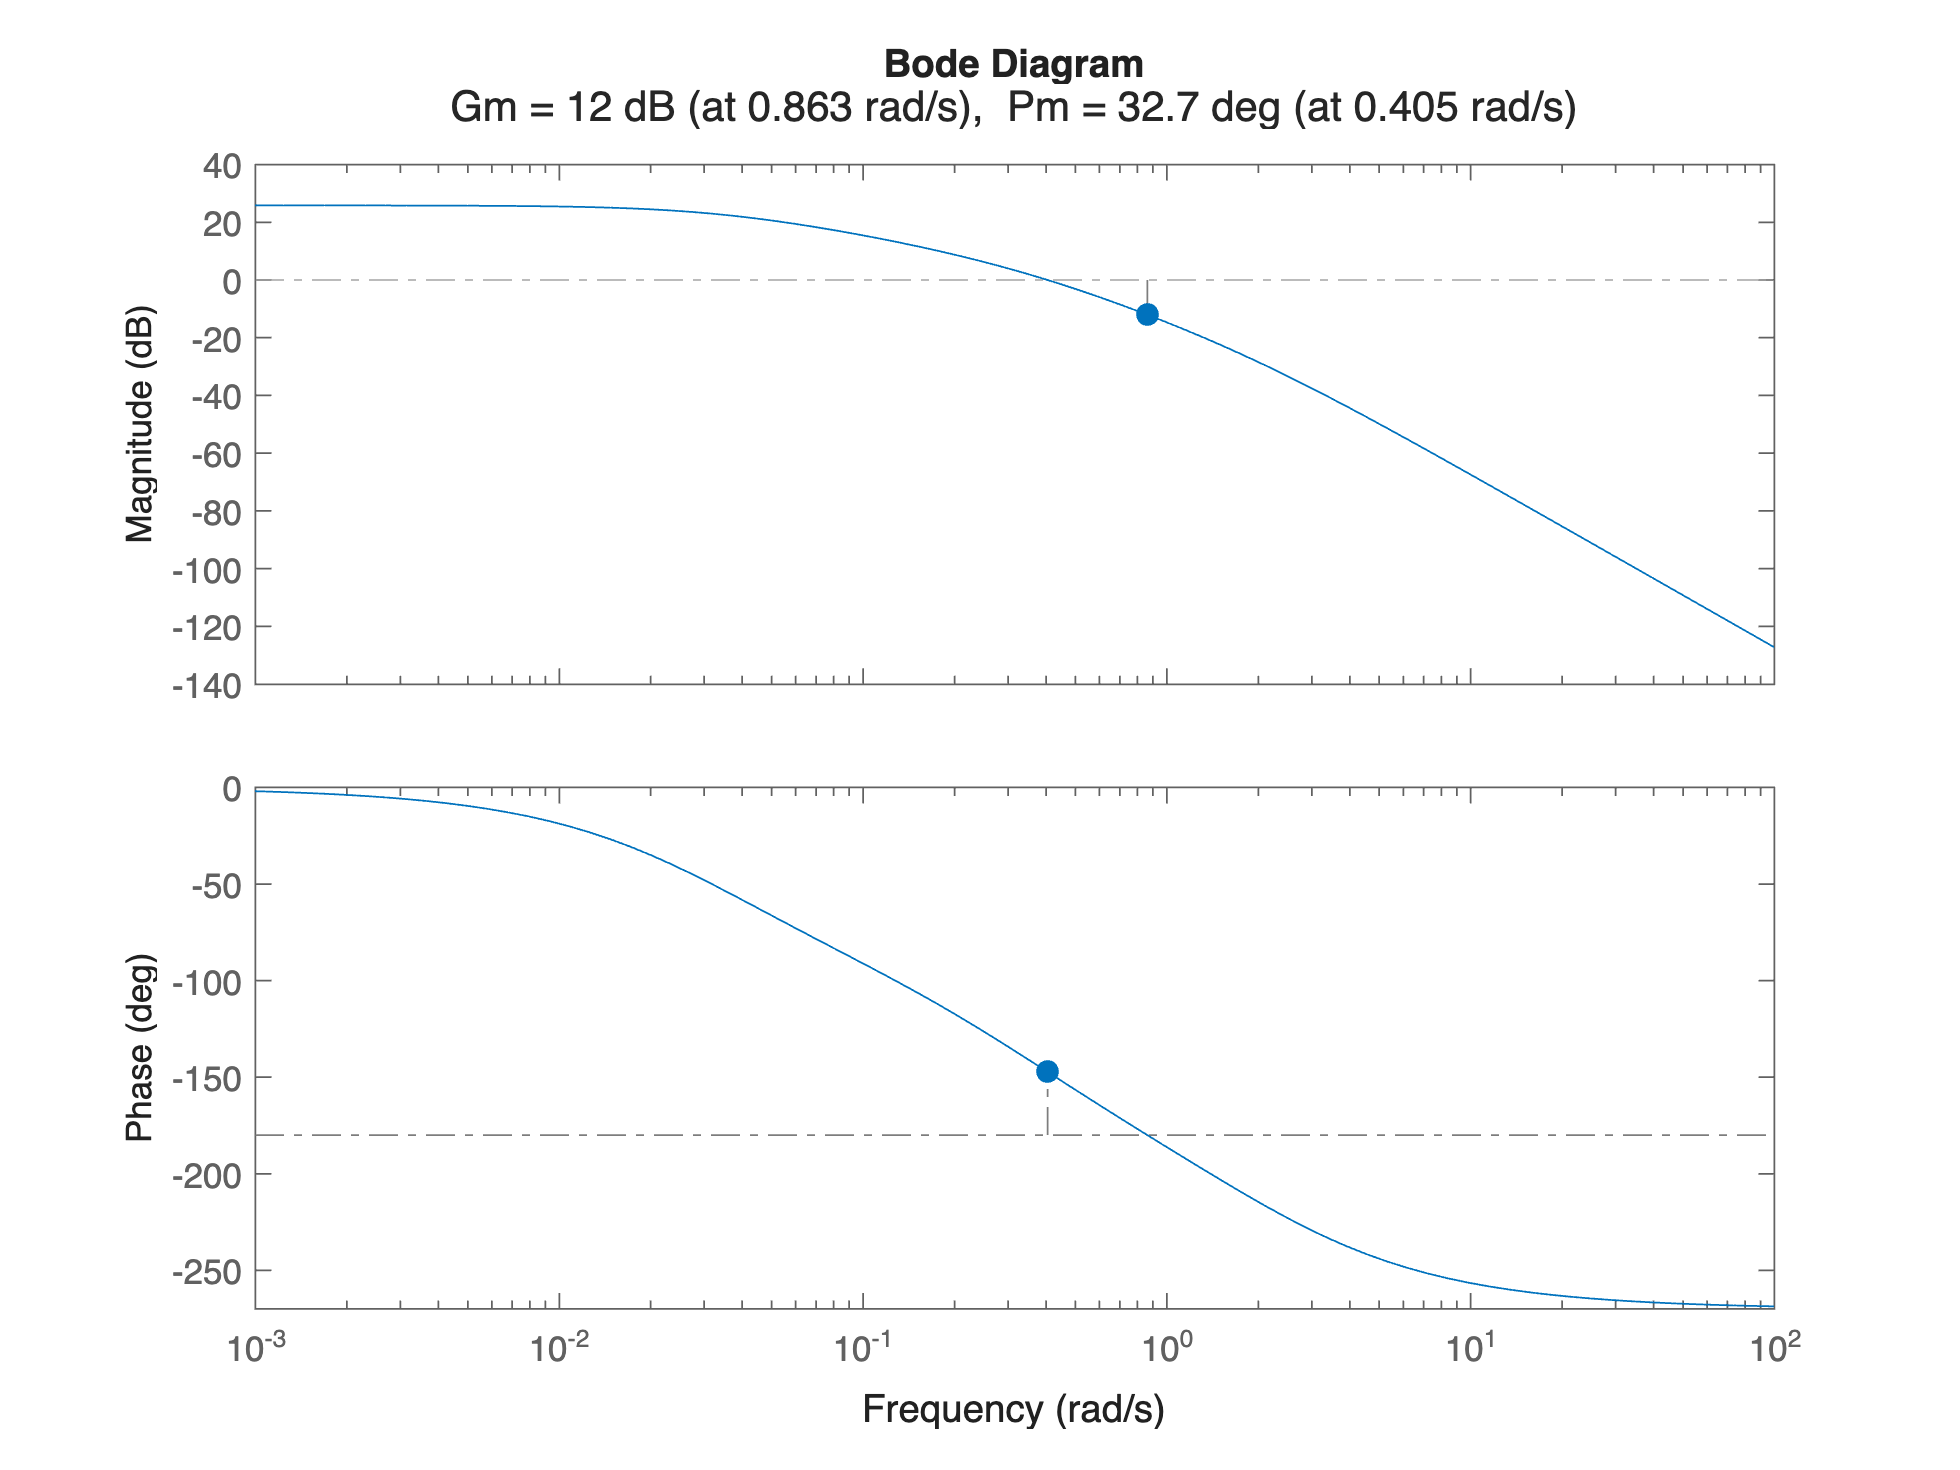

C1s_A1_4 = tf(K1_A1_4);

L1s_A1_4 = C1s_A1_4*F2s*G2s;

figure; margin(L1s_A1_4)

#### A1.5: Crossover Frequency and Phase Margin

Simply

[gainM_2loop, phaseM_2loop, OM_GM_2loop, OM_PM_2loop]= margin(L1s_A1_4)

gainM_2loop = 4.0001

phaseM_2loop = 32.7168

OM_GM_2loop = 0.8628

OM_PM_2loop = 0.4050

#### First Approach: a Recap

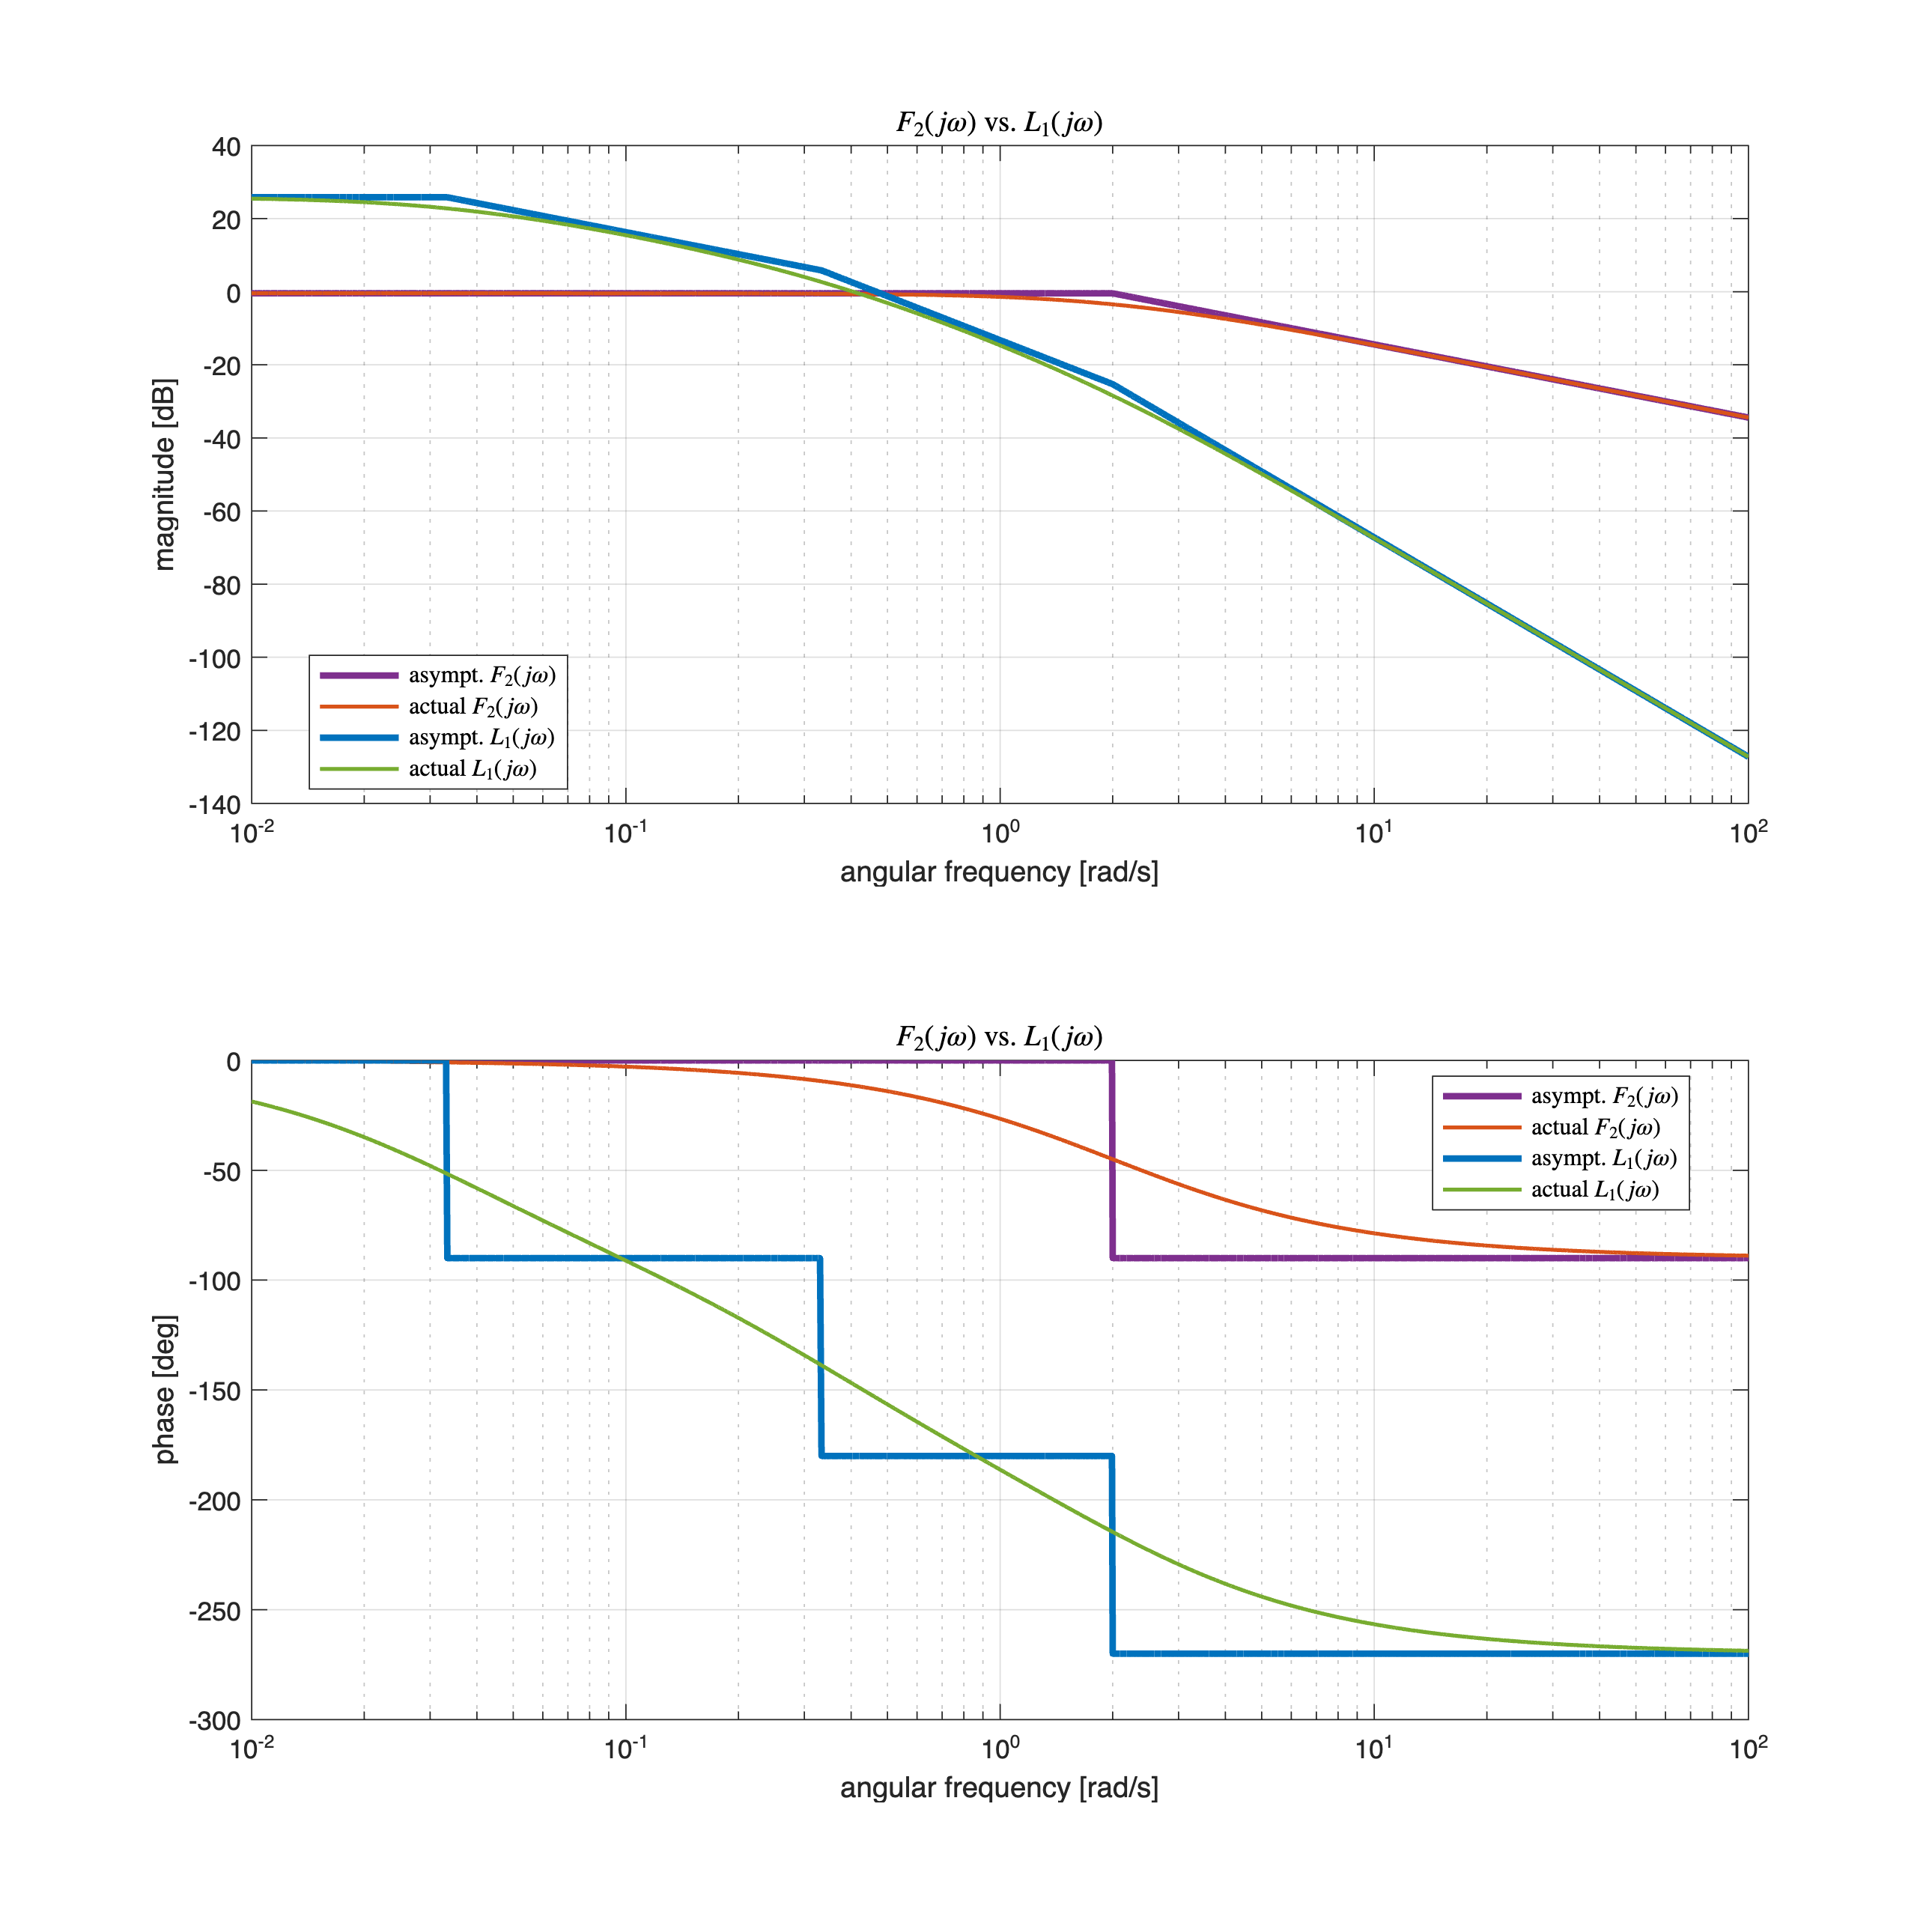

% --- the inner loop controller C2s ---
K2 = +19; 
C2s = tf(K2);
% let's compute the open-loop TF of the inner loop L2s
L2s = C2s*G1s;    % the open-loop TF

F2s = feedback(L2s, 1, -1);

% --- the outer loop controller C1s ---
C1s_A1_4 = tf(K1_A1_4);

L1s_A1_4 = C1s_A1_4*F2s*G2s;


% ----- final Bode plots -----
hf3 = figure('Units','centimeters', 'Position',[0.1,0.1, 26, 26]);


omVALS = logspace(-2, 2, 1e5); % ang. freqs in [1/100; 100]
[hax1, hax2] = drawBodediagrams(F2s, omVALS, Bcolors(3, :), 2.5, '-', ...
                       Bcolors(6, :), 1.5, '-', hf3); % assignment A1.2

drawBodediagrams(L1s_A1_4, omVALS, Bcolors(1, :), 2.5, '-', ...
                       Bcolors(4, :), 1.5, '-', hf3);

title(hax1, '$F_2(j \omega)$ vs. $L_1(j \omega)$', 'Interpreter', 'latex');
title(hax2, '$F_2(j \omega)$ vs. $L_1(j \omega)$', 'Interpreter', 'latex');

legend(hax1,  'asympt. $F_2(j \omega)$', 'actual $F_2(j \omega)$', ...
             'asympt. $L_1(j \omega)$', 'actual $L_1(j \omega)$','Location', 'best', ...
             'Interpreter', 'latex');
legend(hax2,   'asympt. $F_2(j \omega)$', 'actual $F_2(j \omega)$', ...
             'asympt. $L_1(j \omega)$', 'actual $L_1(j \omega)$','Location', 'best', ...
             'Interpreter', 'latex');

### A1: Final Tuning using the controlSystemDesigner App

For detailed information about `sisoinit( )`

CSDconfig = sisoinit(6); %initialise the Control SYstem Designer with configuration 6
% filling the config structure with the TFs of the control system problem
% the plant TFs
CSDconfig.G1.Value = G1s;
CSDconfig.G2.Value = G2s;
% the controllers
CSDconfig.C1.Value = C1s_A1_4;
CSDconfig.C2.Value = C2s;
% the outer loop OL1
CSDconfig.OL1.Name = 'Outer Loop';
CSDconfig.OL1.View = {'bode','rlocus'};
% the iinner loop OL2
CSDconfig.OL2.Name = 'Inner Loop';
CSDconfig.OL2.View = {'bode','rlocus'};
controlSystemDesigner(CSDconfig)

Every requirement is met. No further tuning is needed.

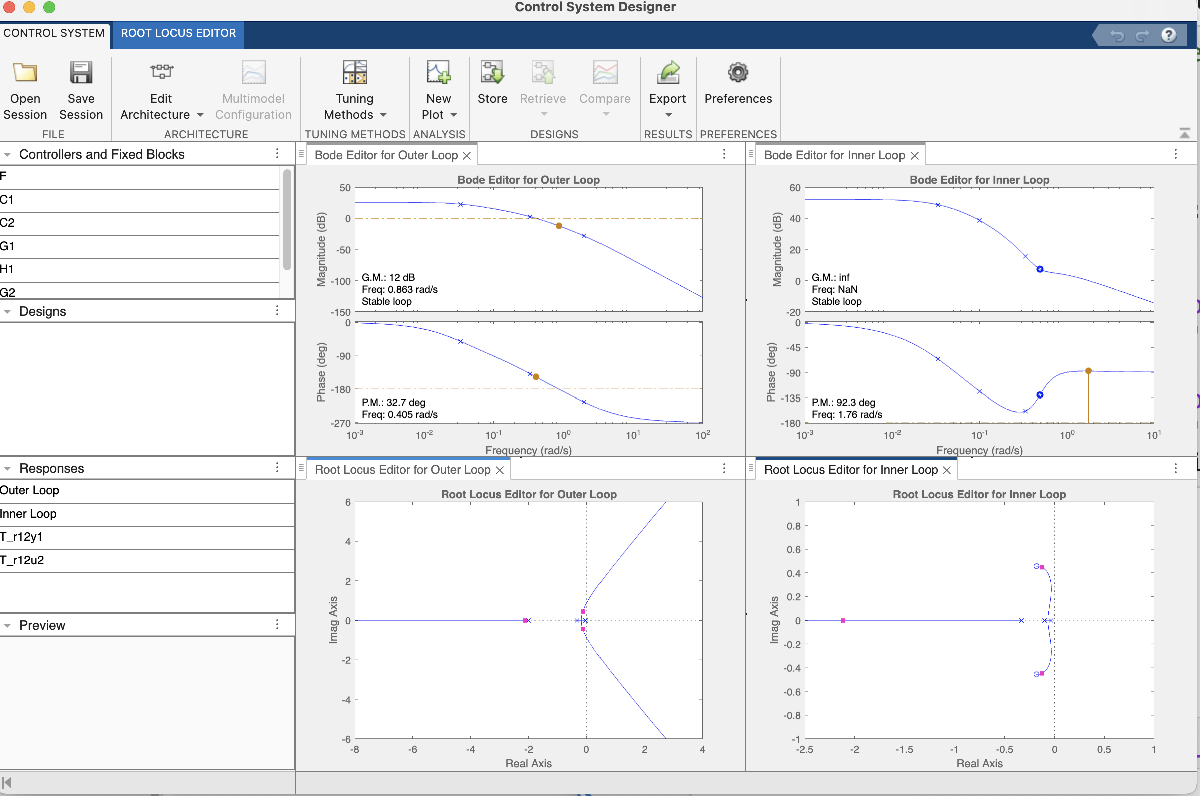

The Control System Designer session data are available in `DESIGN_FA20240902_cSD_session_A1.mat`

### Second Approach: a Single-Loop Scheme

#### A2.1: The Open-Loop Transfer Function

In this scenario there is only a simple feedback loop, thus the open-loop transfer function becomes


$$\hat{L}(s) = C_3(s) \cdot G_1(s) \cdot G_2(s) \; \Longrightarrow \; \hat{L}(s) = \frac{k_3}{\left(10s+1  \right) \cdot \left(30s+1  \right) \cdot \left(3s+1  \right)}$$


K3 = 1; % initial value for the controller gain
C3s = tf(K3); % the P controller

% --- the single-loop open-loop transfer function ---
hatLs = C3s * G1s * G2s;


#### A2.2: the Bode Plots of the Open-Loop Transfer Function

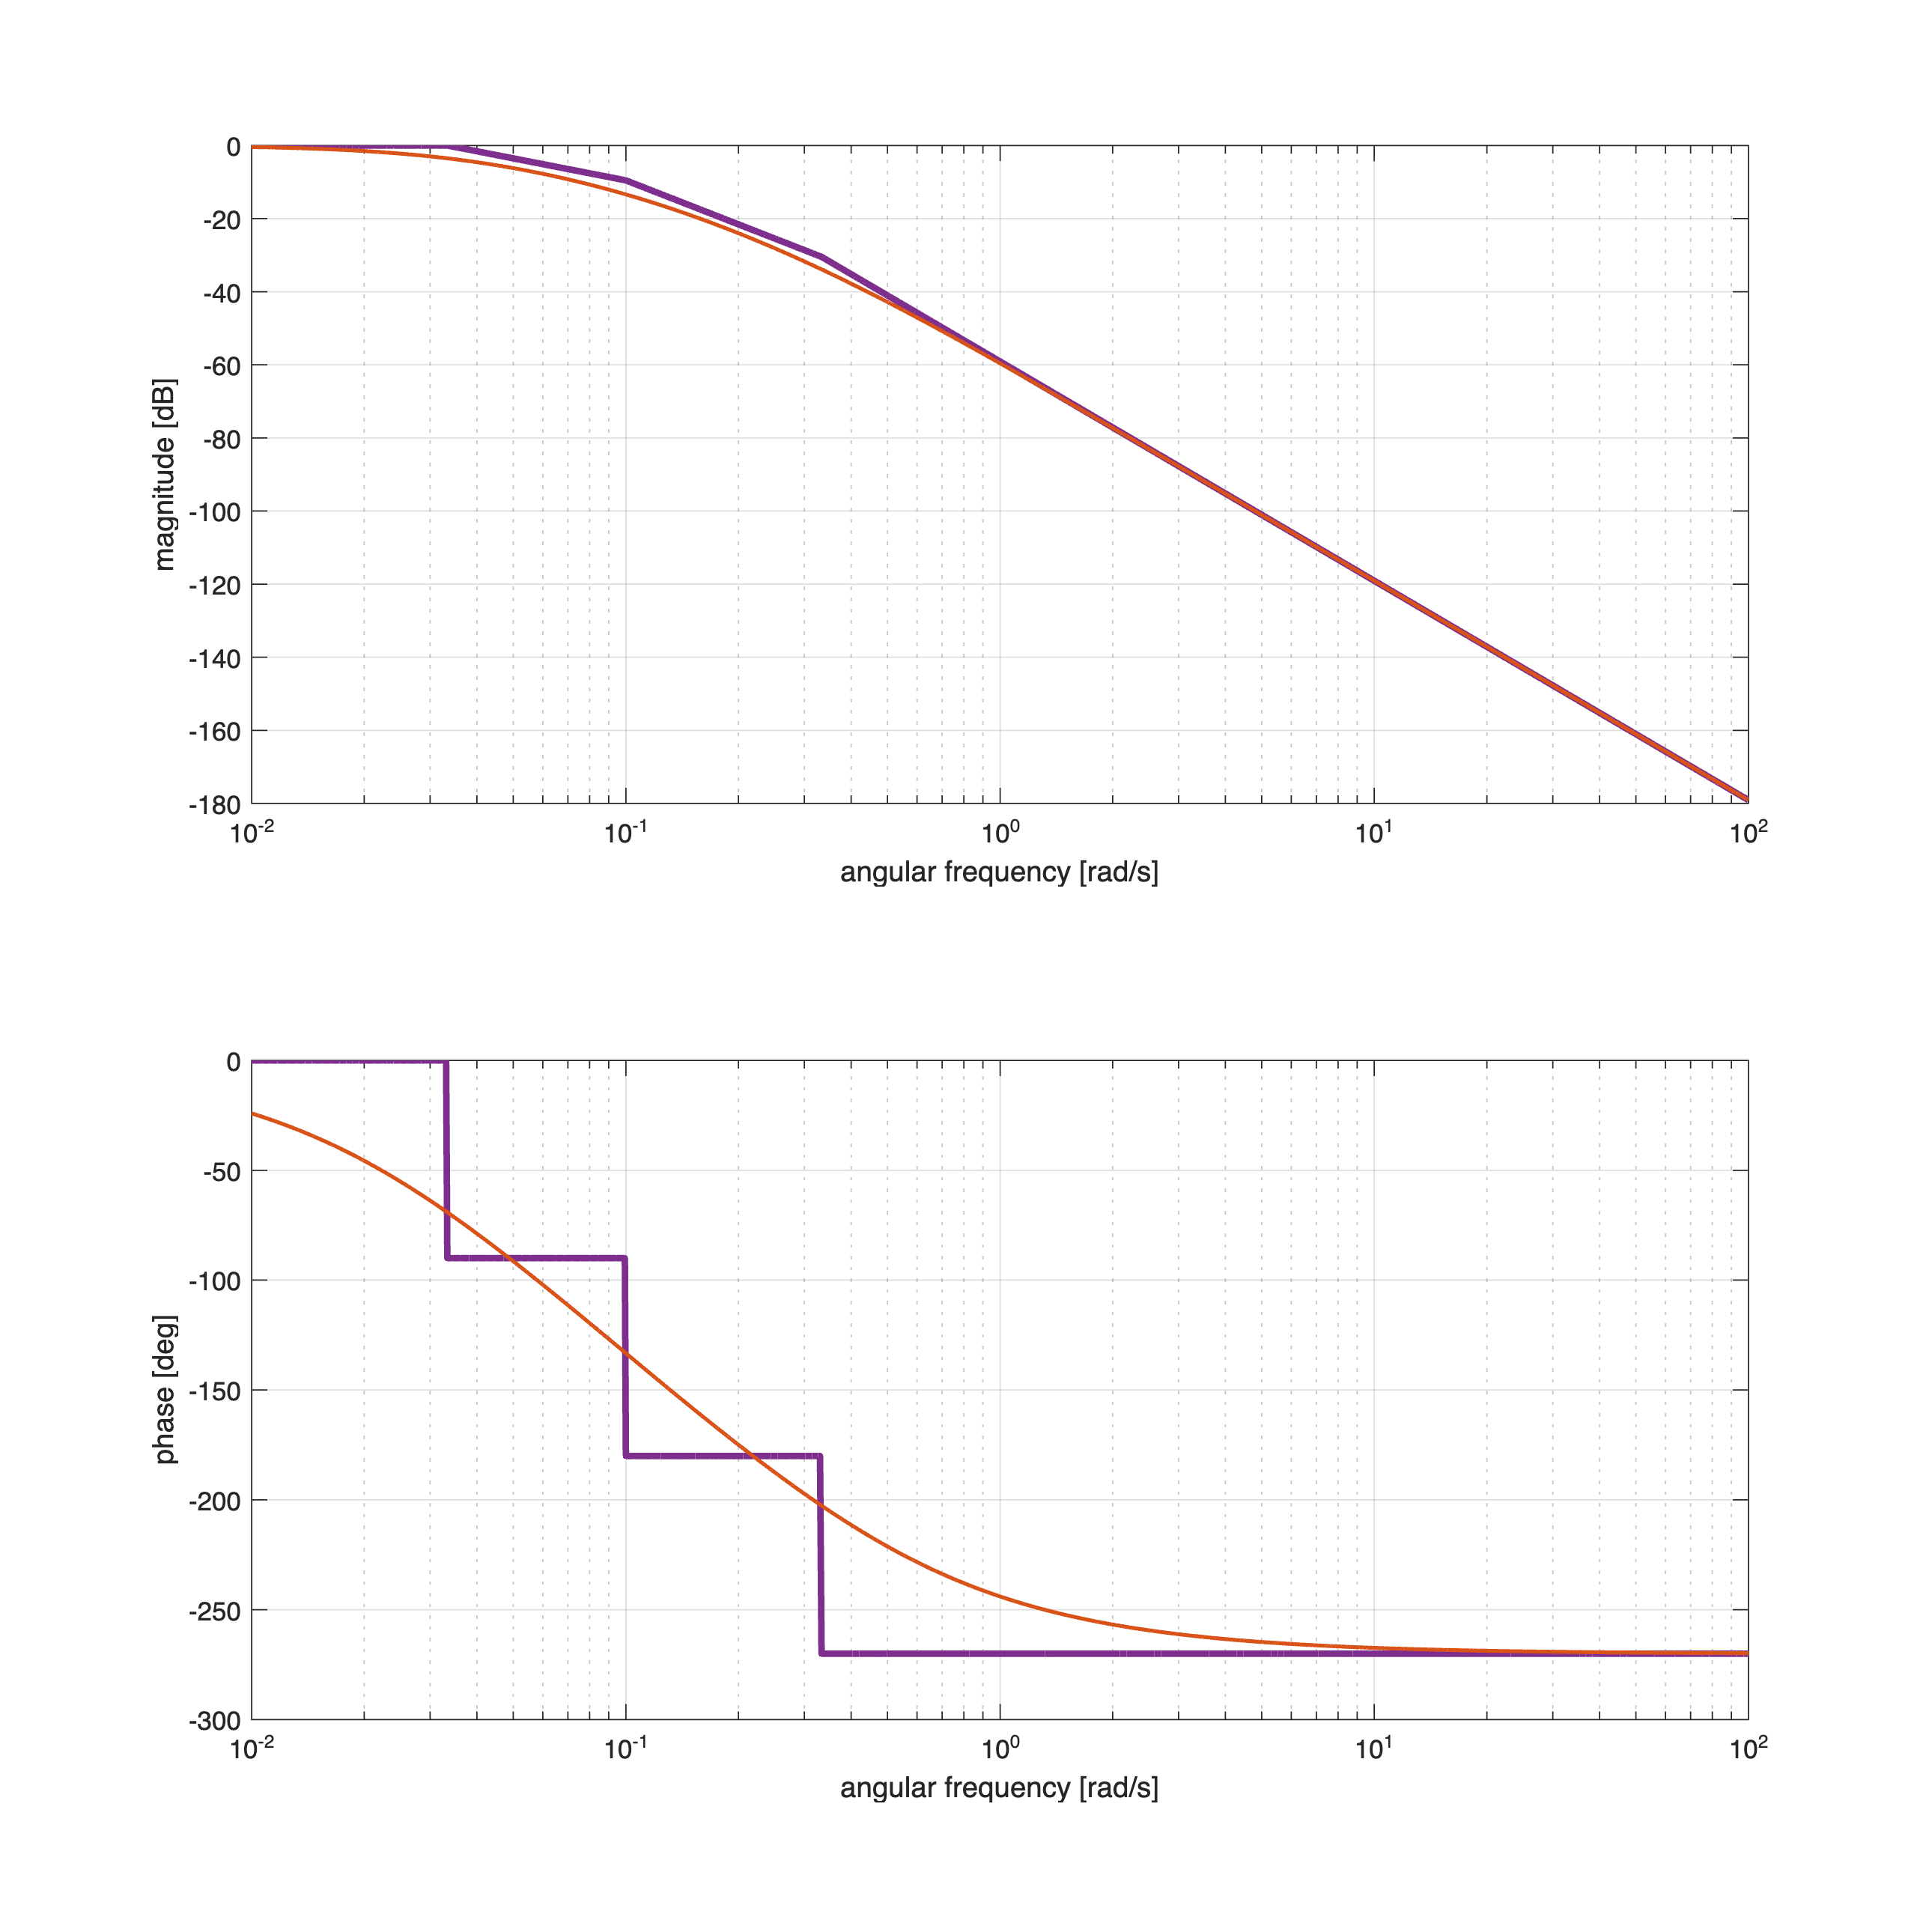

hf4 = figure('Units','centimeters', 'Position',[0.1,0.1, 26, 26]);


omVALS = logspace(-2, 2, 1e5); % ang. freqs in [1/100; 100]
[hax5, hax6] = drawBodediagrams(hatLs, omVALS, Bcolors(3, :), 2.5, '-', ...
                       Bcolors(6, :), 1.5, '-', hf4); % assignment A2.2

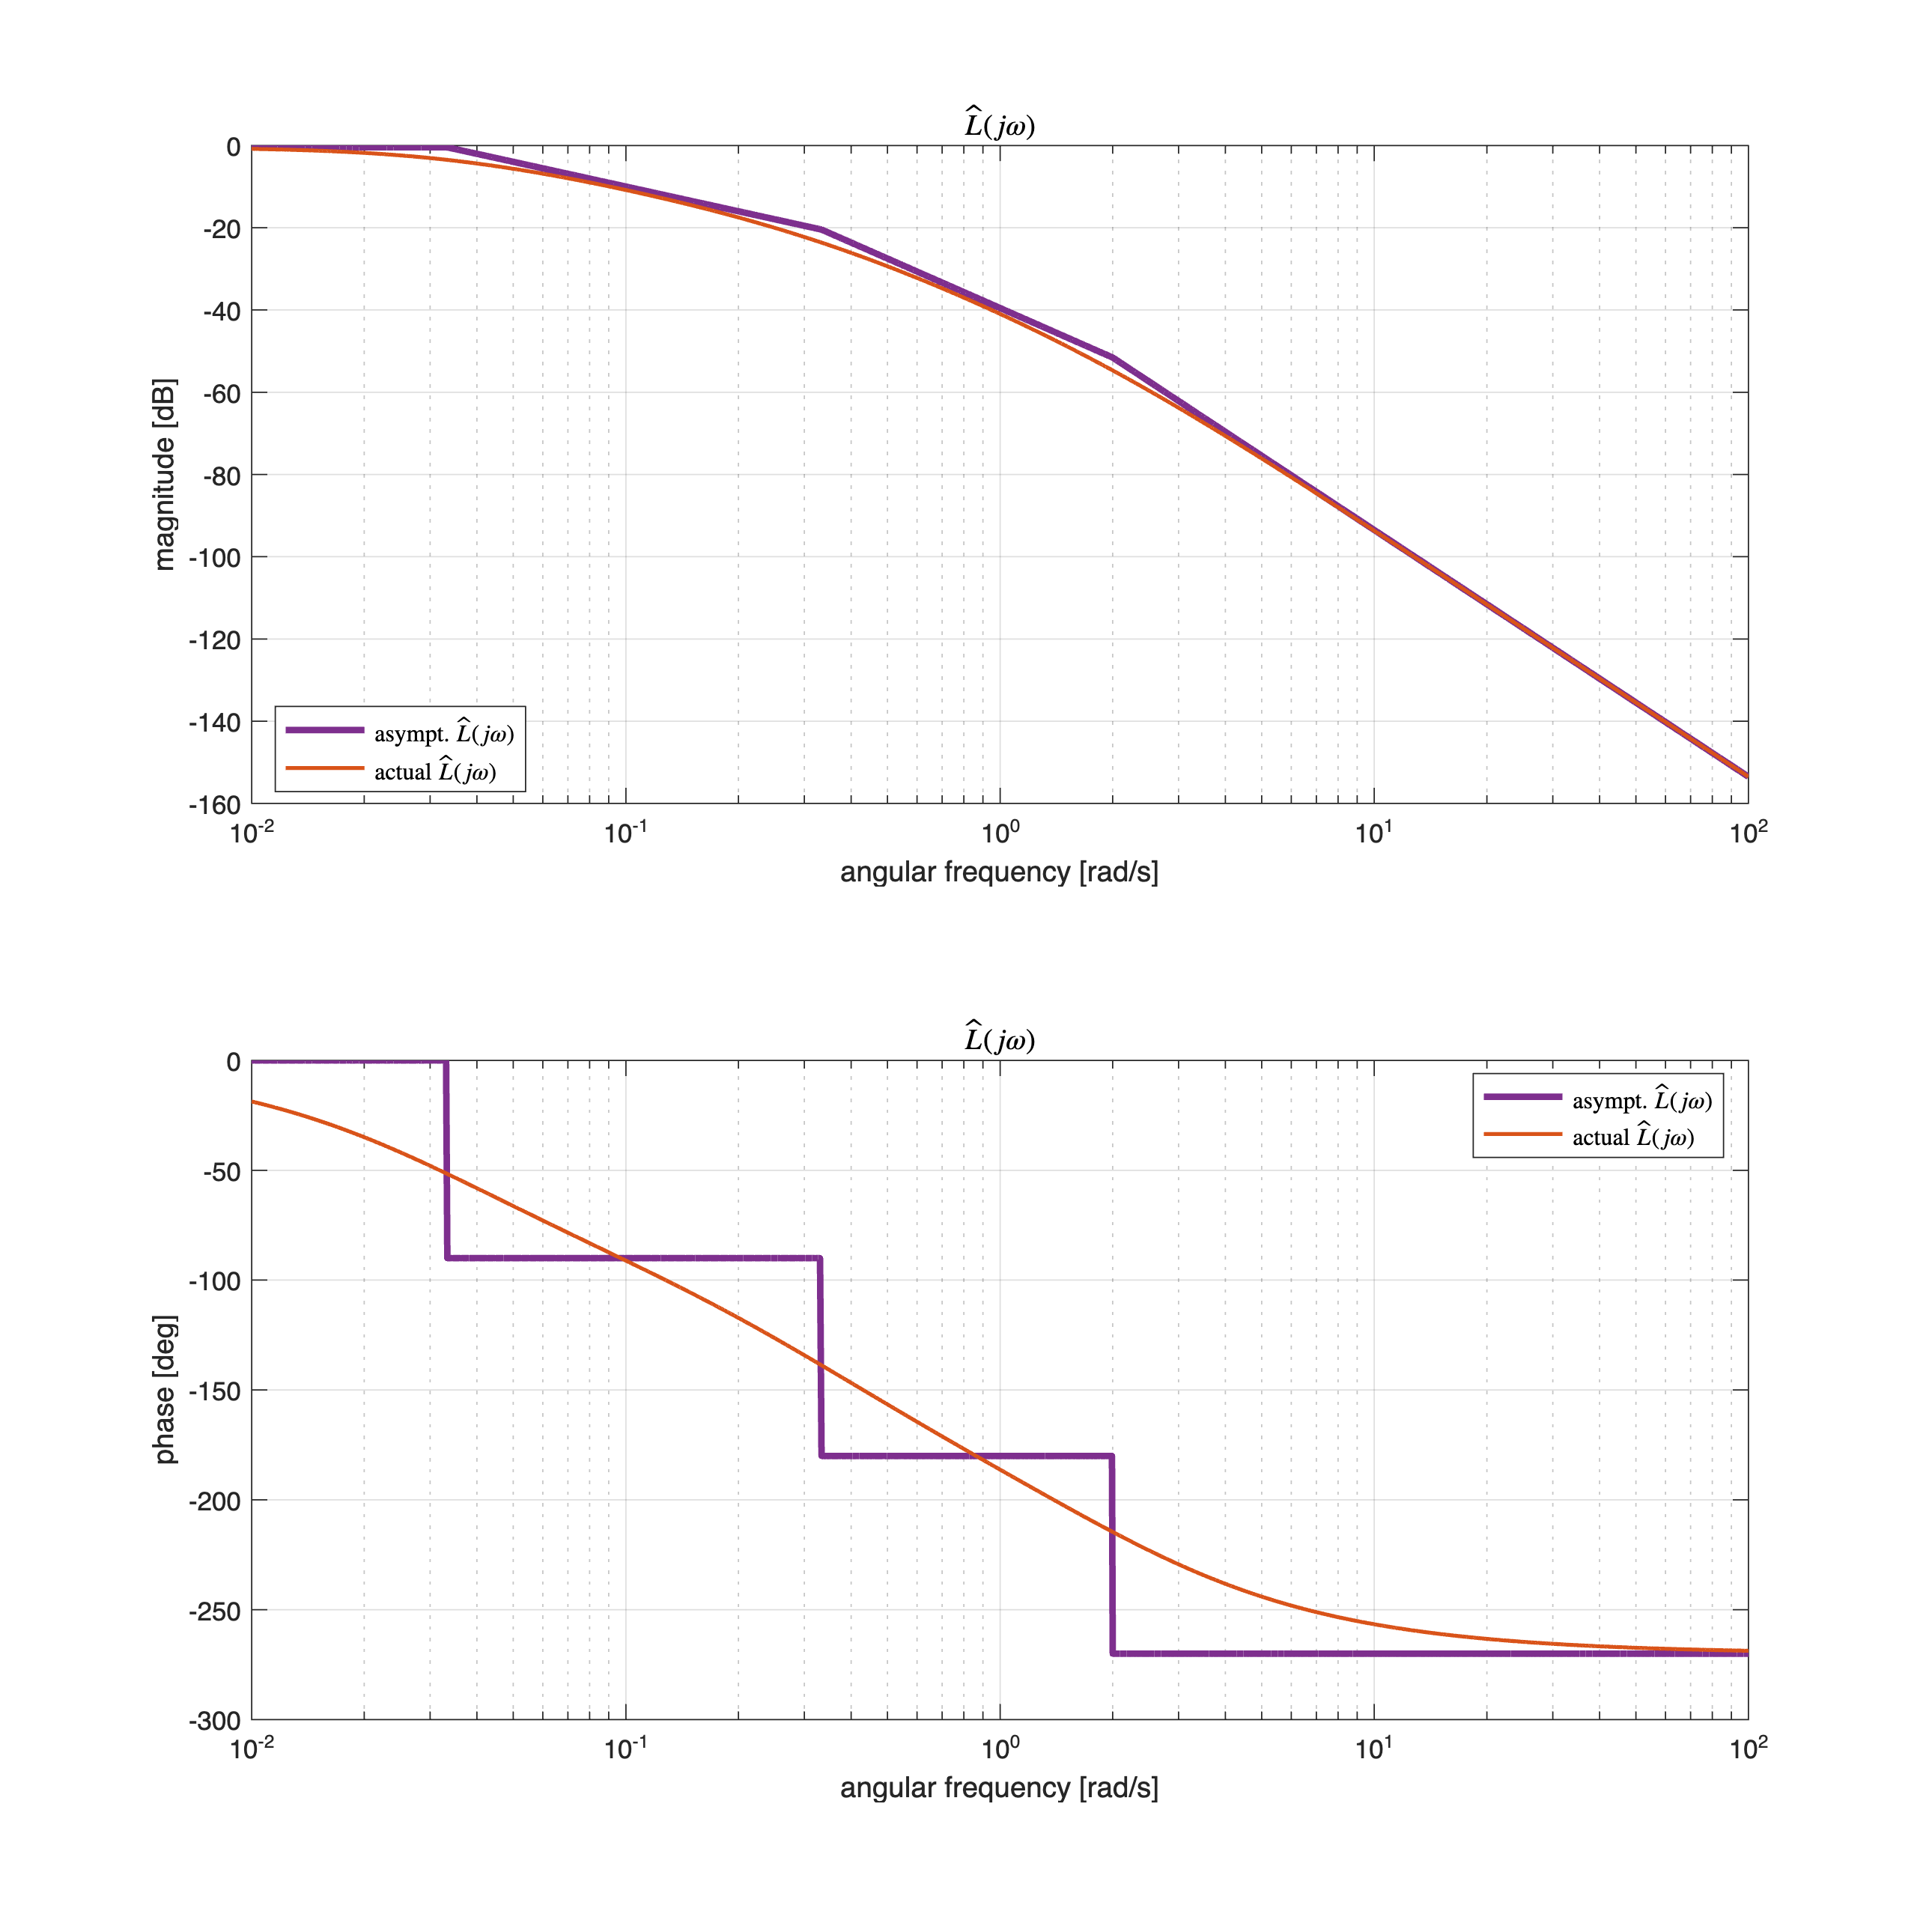


title(hax3, '$\hat{L}(j \omega)$', 'Interpreter', 'latex');
title(hax4, '$\hat{L}(j \omega)$', 'Interpreter', 'latex');

legend(hax3,  'asympt. $\hat{L}(j \omega)$', 'actual $\hat{L}(j \omega)$', ...
              'Location', 'best', ...
             'Interpreter', 'latex');
legend(hax4,  'asympt. $\hat{L}(j \omega)$', 'actual $\hat{L}(j \omega)$', ...
              'Location', 'best', ...
             'Interpreter', 'latex');

#### A2.3: The Comparison of the Open-Loop Frequency Responses in both the Scenarios

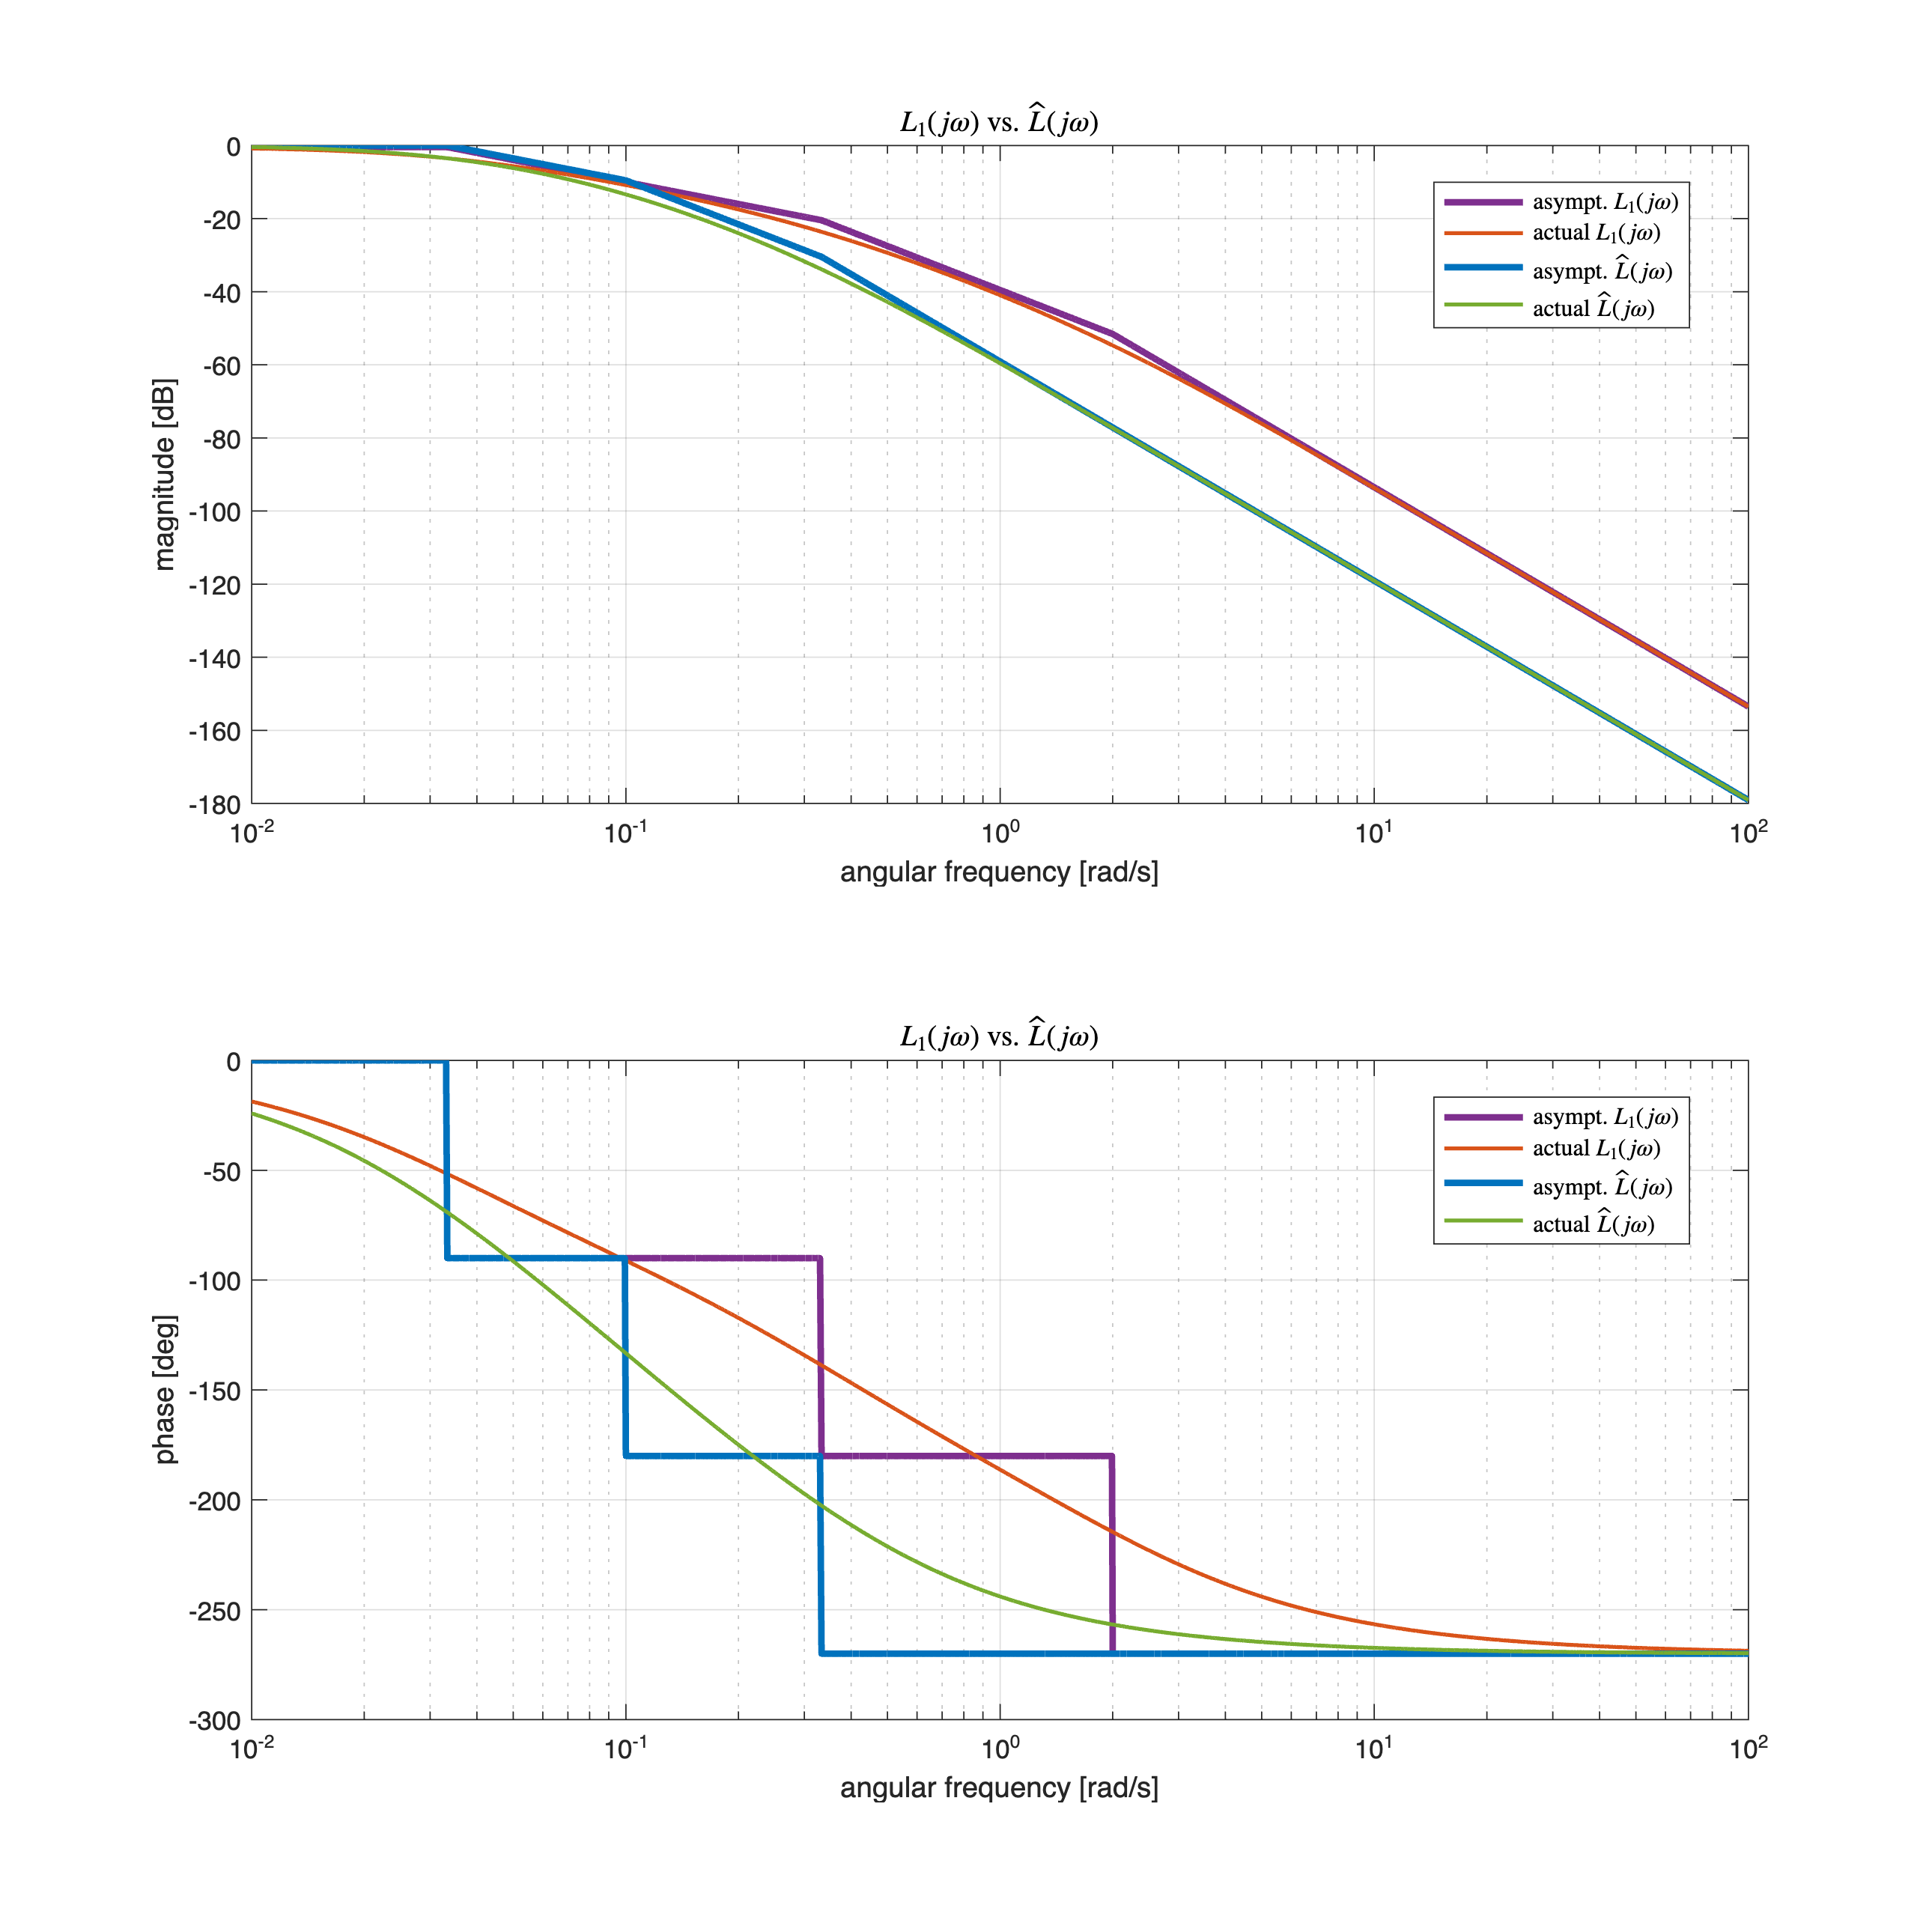

% ----- comparing L1s with hatLs -----
hf5 = figure('Units','centimeters', 'Position',[0.1,0.1, 26, 26]);


omVALS = logspace(-2, 2, 1e5); % ang. freqs in [1/100; 100]
[hax5, hax6] = drawBodediagrams(L1s, omVALS, Bcolors(3, :), 2.5, '-', ...
                       Bcolors(6, :), 1.5, '-', hf5); % assignment A1.2

drawBodediagrams(hatLs, omVALS, Bcolors(1, :), 2.5, '-', ...
                       Bcolors(4, :), 1.5, '-', hf5);

title(hax5, '$L_1(j \omega)$ vs. $\hat{L}(j \omega)$', 'Interpreter', 'latex');
title(hax6, '$L_1(j \omega)$ vs. $\hat{L}(j \omega)$', 'Interpreter', 'latex');

legend(hax5,  'asympt. $L_1(j \omega)$', 'actual $L_1(j \omega)$', ...
             'asympt. $\hat{L}(j \omega)$', 'actual $\hat{L}(j \omega)$','Location', 'best', ...
             'Interpreter', 'latex');
legend(hax6,   'asympt. $L_1(j \omega)$', 'actual $L_1(j \omega)$', ...
             'asympt. $\hat{L}(j \omega)$', 'actual $\hat{L}(j \omega)$','Location', 'best', ...
             'Interpreter', 'latex');

**Remark**: To point out some important different features, let's evaluate the stabiility margin for both the transfer functions $L_1(s)$ (with $k_1=1$ and $k_2=19$) and $\hat{L}(s)$ (with $k_3=1$)

[G1, P1, OMG1, OMP1] = margin(L1s)

G1 = 82.4061

P1 = Inf

OMG1 = 0.8628

OMP1 = NaN

[Gh, Ph, OMgh, OMPh] = margin(hatLs)

Gh = 19.0667

Ph = -180

OMgh = 0.2186

OMPh = 0

The open-loop transfer function $\hat{L}(s)$ performs worse than $L_1(s)$ in the first scenario.

#### A2.4: Tuning the Controller

Given the controller $C_3(s) = k_3$, the open-loop transfer function results


$$\hat{L}(s) = C_3(s) \cdot G_1(s) \cdot G_2(s) \; \Longrightarrow \; \hat{L}(s) = \frac{k_3}{\left(10s+1  \right) \cdot \left(30s+1  \right) \cdot \left(3s+1  \right)}$$


In order to properly tune the controller, let's perform the same algorithm as in the previous scenario:

- find the angular frequency $\hat{\omega}_{\pi}$, such that $\arg \hat{L}(j \hat{\omega}_{\pi}) = -180^{\degree}$. This frequency exists for sure, as pointed out by the Bode plots in A2.2.

- evaluate the frequency response magnitude $|\hat{L}(j \hat{\omega}_{\pi} ) |$ when $k_3=1$ 

- calculate the proper gain value $\bar k_3$such that the requiirement on the gain margin is met.

**First** **approach**: exploiting the Matlab command `margin( )`

[~, ~, omega_pi_approx, ~] = margin(hatLs)

omega_pi_approx = 0.2186

rad2deg(angle(freqresp(hatLs, omega_pi_approx)))

ans = 179.9999

**Second** **approach**: applying some mathematical manipulations. 

As suggested, let's calculate the angular frequency $\hat{\omega}_{\pi}$ as


$$\hat{\omega}_{\pi}: \arg \hat{L}(\j \hat{\omega}_{\pi}) = -180^{\degree} \; \Longleftrightarrow \; \arg \left( k_3 \right) - \arg \big[ \left( 10\,j \hat{\omega}_{\pi}+1 \right) \left(  30\,j \hat{\omega}_{\pi}+1\right) \left( 3\,j \hat{\omega}_{\pi}+1 \right) \big] = -180^{\degree}$$


Assuming $k_3 >0$, we obtain


$$\hat{\omega}_{\pi}: \arg \hat{L}(\j \hat{\omega}_{\pi}) = -180^{\degree} \; \Longleftrightarrow \;  - \arg \big[ \left( 10\,j \hat{\omega}_{\pi}+1 \right) \left(  30\,j \hat{\omega}_{\pi}+1\right) \left( 3\,j \hat{\omega}_{\pi}+1 \right) \big] = -180^{\degree}$$


Thus


$$\hat{\omega}_{\pi}: \arg \hat{L}(\j \hat{\omega}_{\pi}) = -180^{\degree} \; \Longleftrightarrow \;  \arg \big[ \left(10\,j \hat{\omega}_{\pi}+1 \right) \big] + \arg \big[ \left(  30\,j \hat{\omega}_{\pi}+1\right)\big] + \arg \big[ \left( 3\,j \hat{\omega}_{\pi}+1 \right) \big] = 180^{\degree}$$



$$ \arg \big[ \left(  30\,j \hat{\omega}_{\pi}+1\right)\big] + \arg \big[ \left( 3\,j \hat{\omega}_{\pi}+1 \right) \big] = 180^{\degree} - \arg \big[ \left( 10\,j \hat{\omega}_{\pi}+1 \right) \big] $$


Since $\hat{\omega}_{\pi} >0$


$$\arctan \left( \frac{30 \hat{\omega}_{\pi} }{1}\right) + \arctan \left( \frac{3 \hat{\omega}_{\pi} }{1}\right) = 
180^{\degree} - \arctan \left( \frac{10 \hat{\omega}_{\pi} }{1}\right) \; \Longleftrightarrow \; 
\arctan \left(30 \hat{\omega}_{\pi} \right) + \arctan \left(3 \hat{\omega}_{\pi}\right) = 
180^{\degree} - \arctan \left(10 \hat{\omega}_{\pi}\right)$$


Given the trigonometric identities


$$\tan \left( \alpha+\beta \right) = \frac{\tan (\alpha) + \tan( \beta)}{1-\tan (\alpha) \tan (\beta)} \quad
\alpha+\beta \neq 90^{\degree} + n 180^{\degree}\,,\; n \in \mathbb{Z}$$


and


$$\tan \left(180^{\degree} - \delta \right) = - \tan \delta$$


we obtain


$$\arctan \left(30 \hat{\omega}_{\pi} \right) + \arctan \left(3 \hat{\omega}_{\pi}\right) = 
180^{\degree} - \arctan \left(10 \hat{\omega}_{\pi}\right) \; \Longleftrightarrow \;
\frac{33\hat{\omega}_{\pi}}{1-90\hat{\omega}_{\pi}^2} = - 10 \hat{\omega}_{\pi}$$


Assume


$$\hat{\omega}_{\pi} \neq 0\;,\quad 1-90 \hat{\omega}_{\pi}^2 \neq 0\;,\quad \hat{\omega}_{\pi}>0$$


Thus


$$\frac{33\hat{\omega}_{\pi}}{1-90\hat{\omega}_{\pi}^2} = - 10 \hat{\omega}_{\pi} \; \Longleftrightarrow \;
\frac{33}{1-90\hat{\omega}_{\pi}^2} = - 10  \; \Longleftrightarrow \;
\frac{33}{10} = - \left( 1-90\omega_{\pi}^2 \right)\; \Longleftrightarrow \;
3.3 = 90\hat{\omega}_{\pi}^2-1 \; \Longleftrightarrow \;
 90\hat{\omega}_{\pi}^2 = \frac{43}{10}  \; \Longleftrightarrow \;
\hat{\omega}_{\pi}^2 = \frac{43}{900}$$


Finally


$$\omega_{\pi} = + \frac{\sqrt{43}}{30}$$


syms hat_omega
assume(hat_omega >=0)

OMeq_hat = hat_omega^2 == (43/900); 
hat_omega_pi = solve(OMeq_hat, hat_omega)

$$hat\_omega\_pi = \frac{\sqrt{43}}{30}$$

hat_omega_pi_val = double(hat_omega_pi)

hat_omega_pi_val = 0.2186

rad2deg(angle(freqresp(hatLs,hat_omega_pi_val )))

ans = 180

Now, let's evaluate the **magnitude** of $\hat{L}(j \hat{\omega}_{\pi})$:

Assuming $k_3=1$ we can calculate the magnitude of the frequency response $|\hat{L}(j \hat{\omega}_{\pi}) |$ as follows

mag_hatL_1 = abs(freqresp(hatLs,hat_omega_pi_val ))

mag_hatL_1 = 0.0524

To fulfil A2.4, we have to increase $|\hat{L}(j \hat{\omega}_{\pi}) |$:

gainM_target_dB = +12; % dB
gainM_target = 10^(gainM_target_dB/20)

gainM_target = 3.9811

In fact (refer to Part 9 of the course material, slide 24)


$$K_m = \frac{1}{\left| L(j \omega_{\pi} )\right|}$$


Thus, to obtain $\left. \bar{K}_{m\,\text{dB}} =+12 \;\text{dB}$, the magnitude $\left| \bar{L}_3(j \hat{\omega}_{\pi} \right|$ should have the value


$$\left|  \bar{L}_3(j \hat{\omega}_{\pi}) \right| = \frac{1}{\left. \bar{K}_{m} } \approx \frac{1}{4} \quad 
\Longrightarrow \quad
\bar{k}_1 = \frac{\left|  \bar{L}_3(j \hat{\omega}_{\pi} \right|}{\left| L_3(j \hat{\omega}_{\pi} )\right|}$$


K3_A2_4 = (1/4)/mag_hatL_1

K3_A2_4 = 4.7667

Let's check the effective gain margin, when using this value for the gain $k_1$:

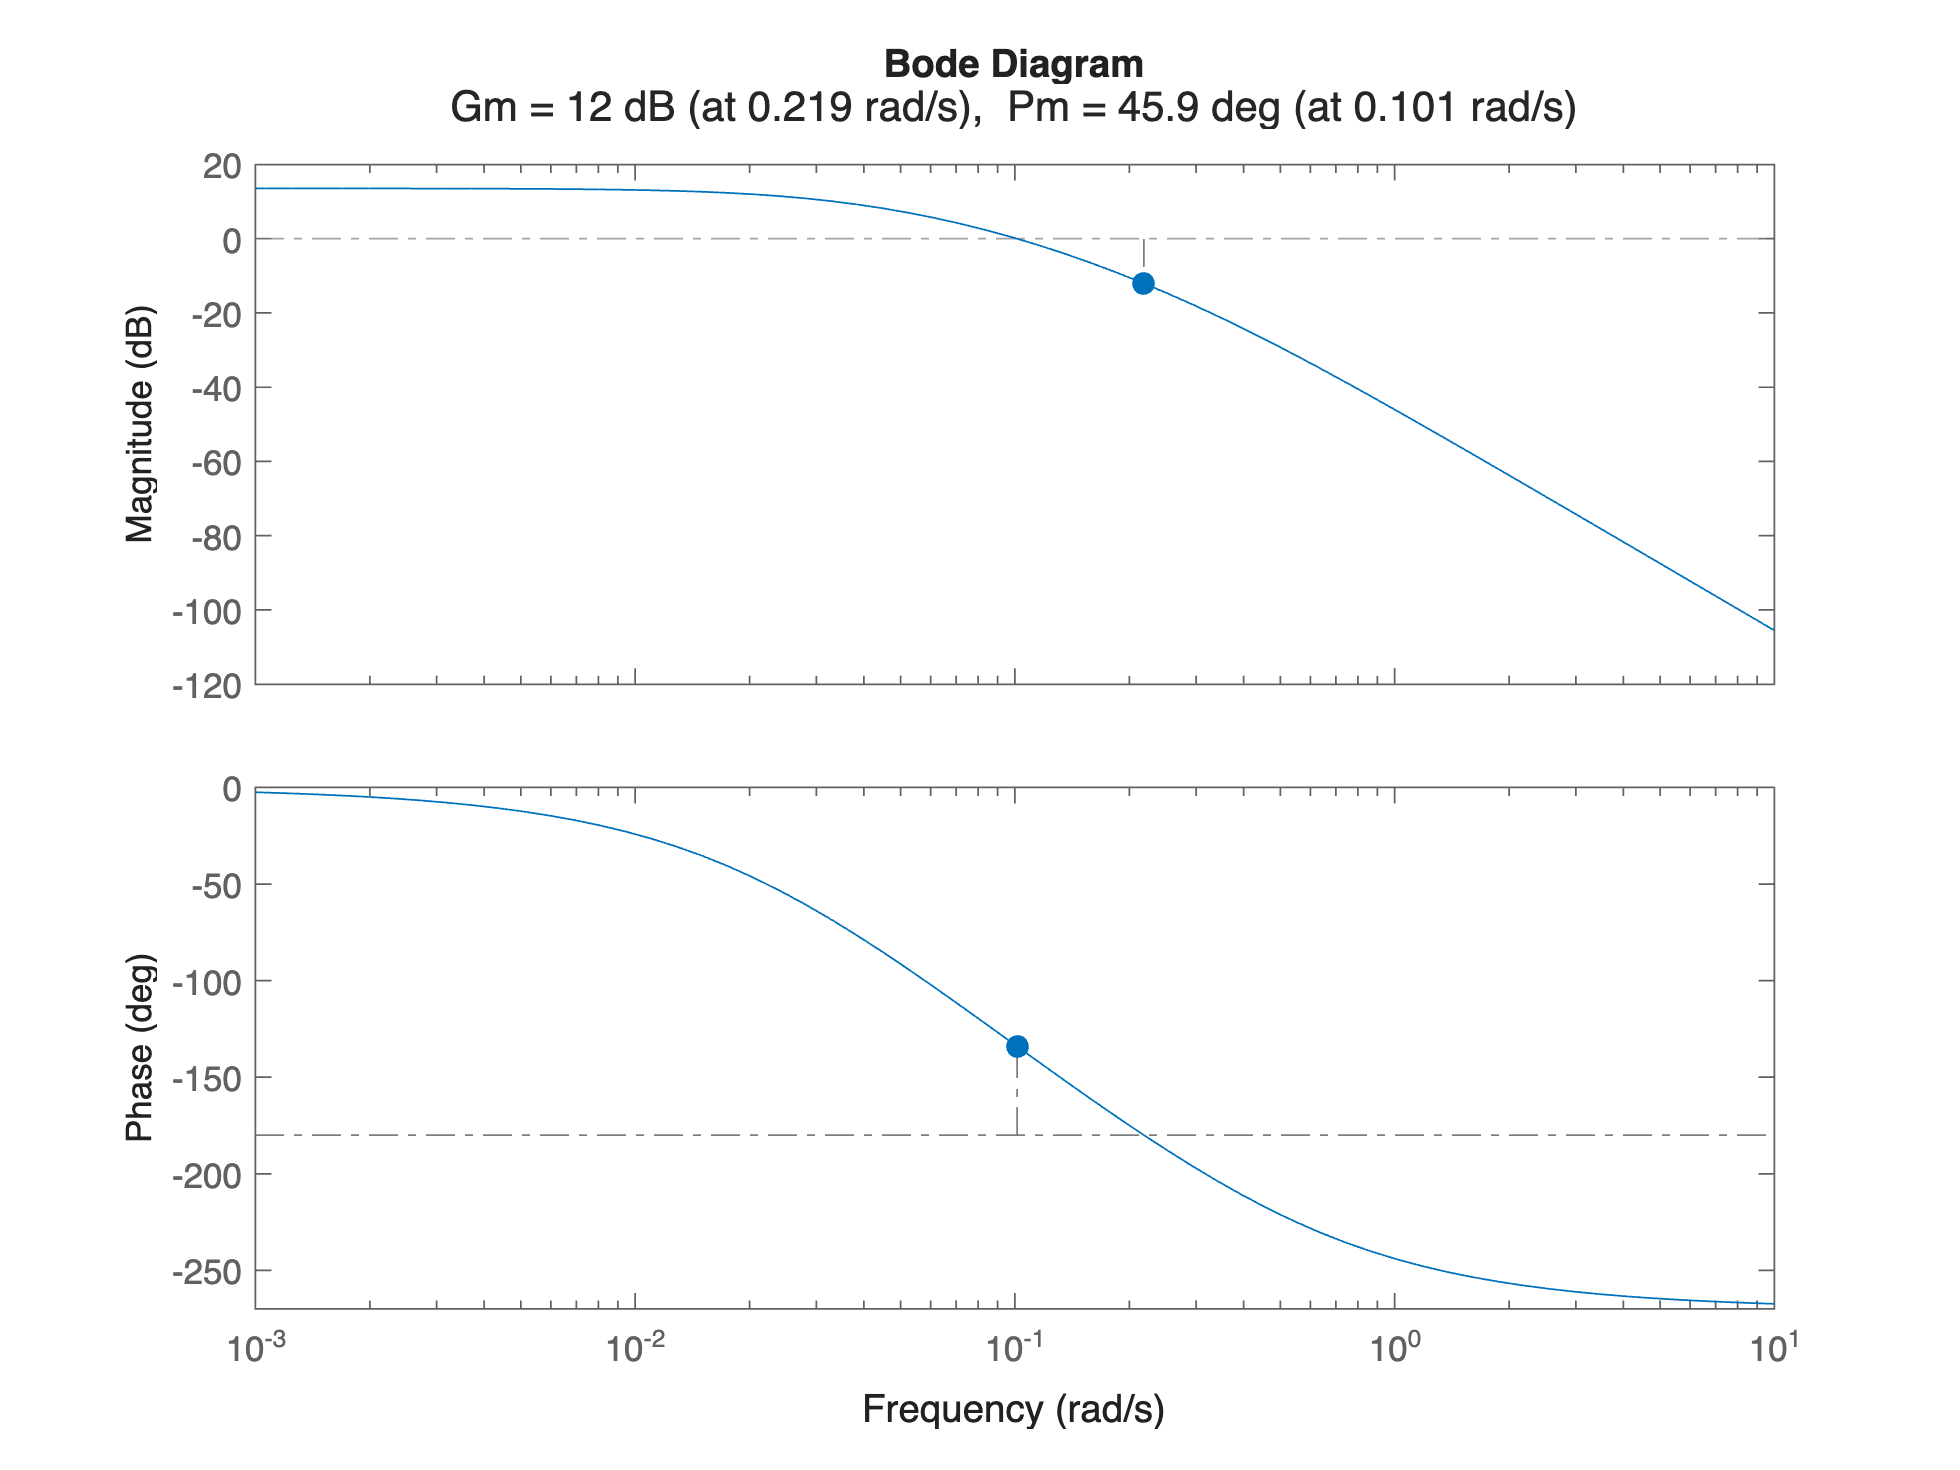

C3s_A2_4 = tf(K3_A2_4);

hatLs_A2_4 = C3s_A2_4*G1s*G2s;

figure; margin(hatLs_A2_4)

#### A2.5: Crossover Frequency and Phase Margin

Simply

[gainM_1loop, phaseM_1loop, OM_GM_1loop, OM_PM_1loop]= margin(hatLs_A2_4)

gainM_1loop = 4.0000

phaseM_1loop = 45.8954

OM_GM_1loop = 0.2186

OM_PM_1loop = 0.1014

#### Second Approach: a Recap

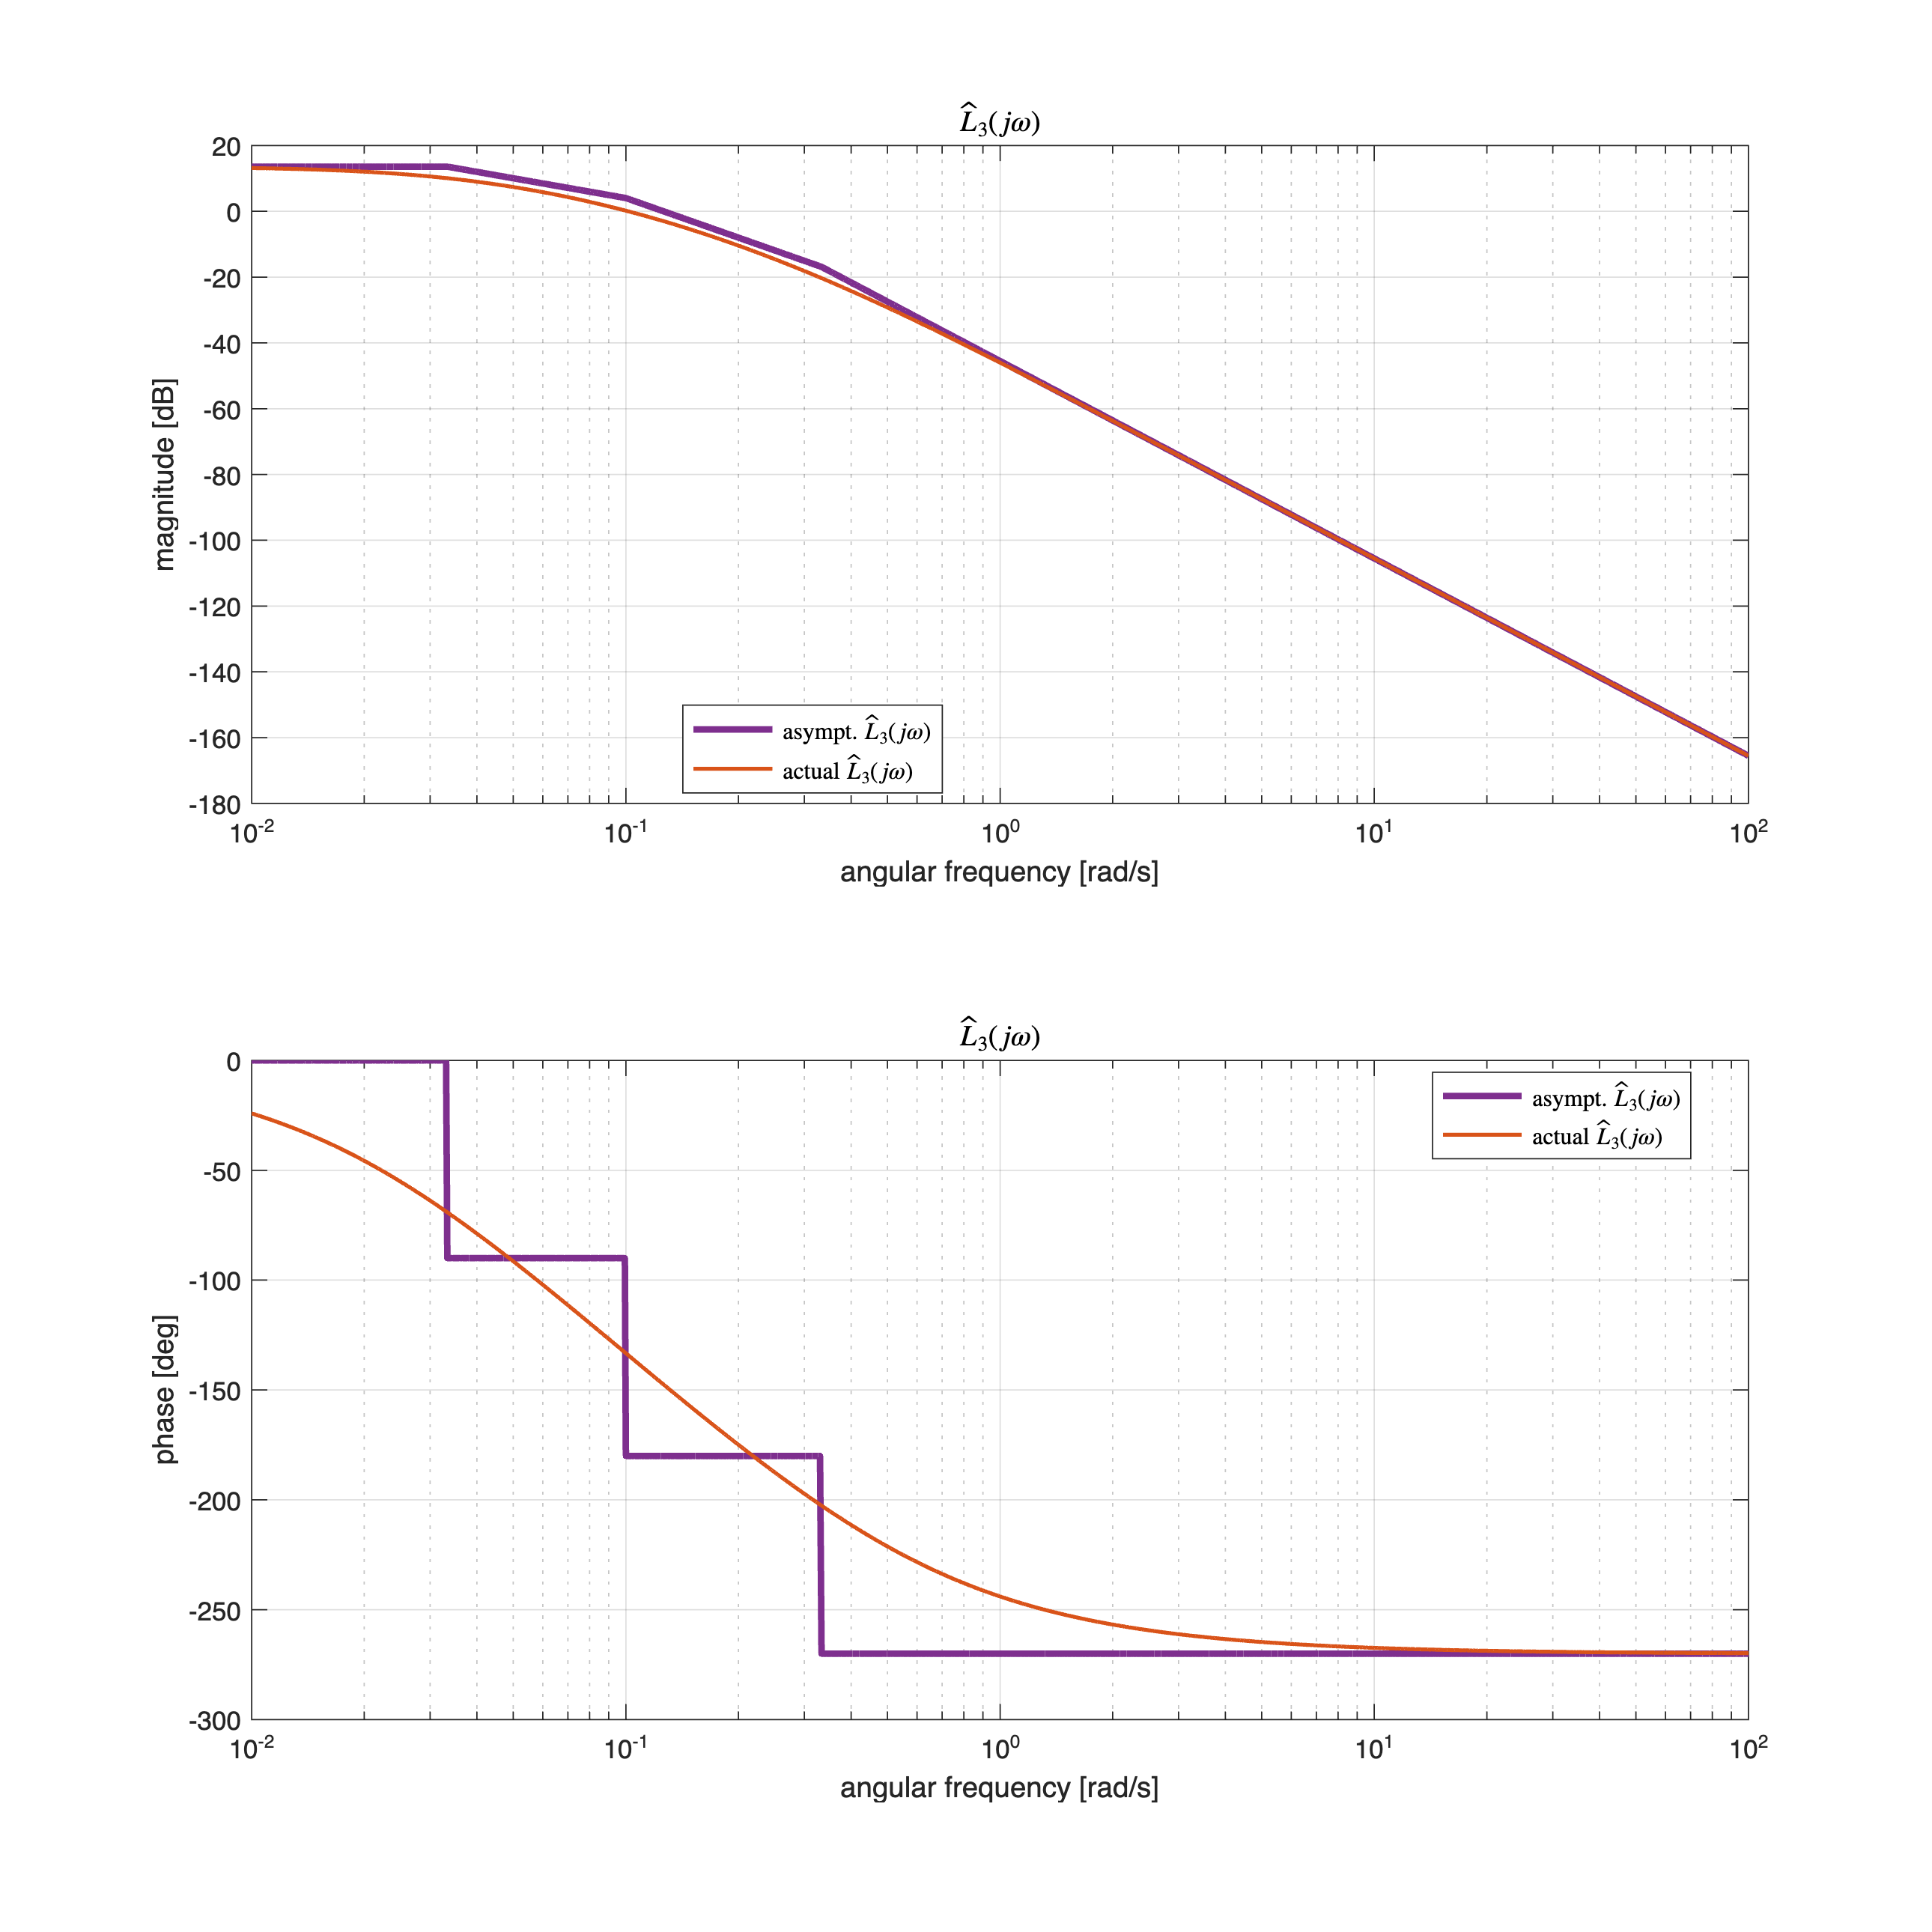

% --- the single loop controller C3s ---
C3s_A2_4 = tf(K3_A2_4);

% let's compute the open-loop TF of the inner loop L2s
hatLs_A2_4 = C3s_A2_4*G1s*G2s;

% ----- final Bode plots -----
hf8 = figure('Units','centimeters', 'Position',[0.1,0.1, 26, 26]);


omVALS = logspace(-2, 2, 1e5); % ang. freqs in [1/100; 100]
[hax1, hax2] = drawBodediagrams(hatLs_A2_4, omVALS, Bcolors(3, :), 2.5, '-', ...
                       Bcolors(6, :), 1.5, '-', hf8); % assignment A1.2

title(hax1, '$\hat{L}_3(j \omega)$', 'Interpreter', 'latex');
title(hax2, '$\hat{L}_3(j \omega)$', 'Interpreter', 'latex');

legend(hax1,  'asympt. $\hat{L}_3(j \omega)$', 'actual $\hat{L}_3(j \omega)$', ...
             'Location', 'best', ...
             'Interpreter', 'latex');
legend(hax2, 'asympt. $\hat{L}_3(j \omega)$', 'actual $\hat{L}_3(j \omega)$', ...
             'Location', 'best', ...
             'Interpreter', 'latex');

### A2: Final Tuning using the controlSystemDesigner App

For detailed information about `sisoinit( )`

CSDconfig = sisoinit(1) %initialise the Control SYstem Designer with configuration 1

             Name: ''
      Description: 'Design snapshot.'
     FeedbackSign: -1
            Input: {4×1 cell}
           Output: {2×1 cell}
          Version: 2
    Configuration: 1
         LoopView: [10×1 sisodata.looptransfer]
                C: [1×1 sisodata.TunedZPKSnapshot]
                H: [1×1 sisodata.system]
                G: [1×1 sisodata.system]
              OL1: [1×1 sisodata.TunedLoopSnapshot]
                F: [1×1 sisodata.TunedZPKSnapshot]
              CL1: [1×1 sisodata.TunedLoopSnapshot]



% filling the config structure with the TFs of the control system problem
% the plant TF
CSDconfig.G.Value = G1s*G2s;
% the controller
CSDconfig.C.Value = C3s_A2_4;
% the open loop OL1
CSDconfig.OL1.Name = 'Open Loop TF';
CSDconfig.OL1.View = {'bode','rlocus'};

controlSystemDesigner(CSDconfig)

Every requirement is met. No further tuning is needed.

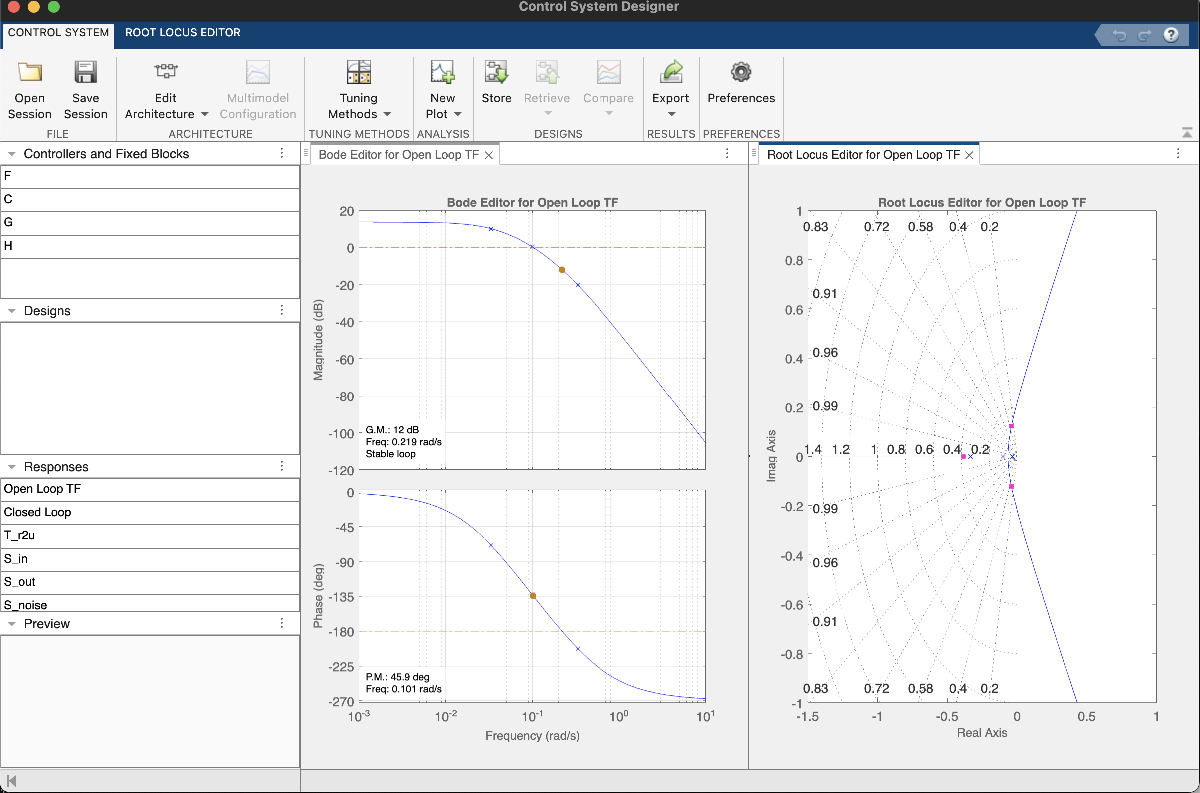

The Control System Designer session data are available in `DESIGN_FA20240902_cSD_session_A2.mat`

### A2.6: Final Comparison

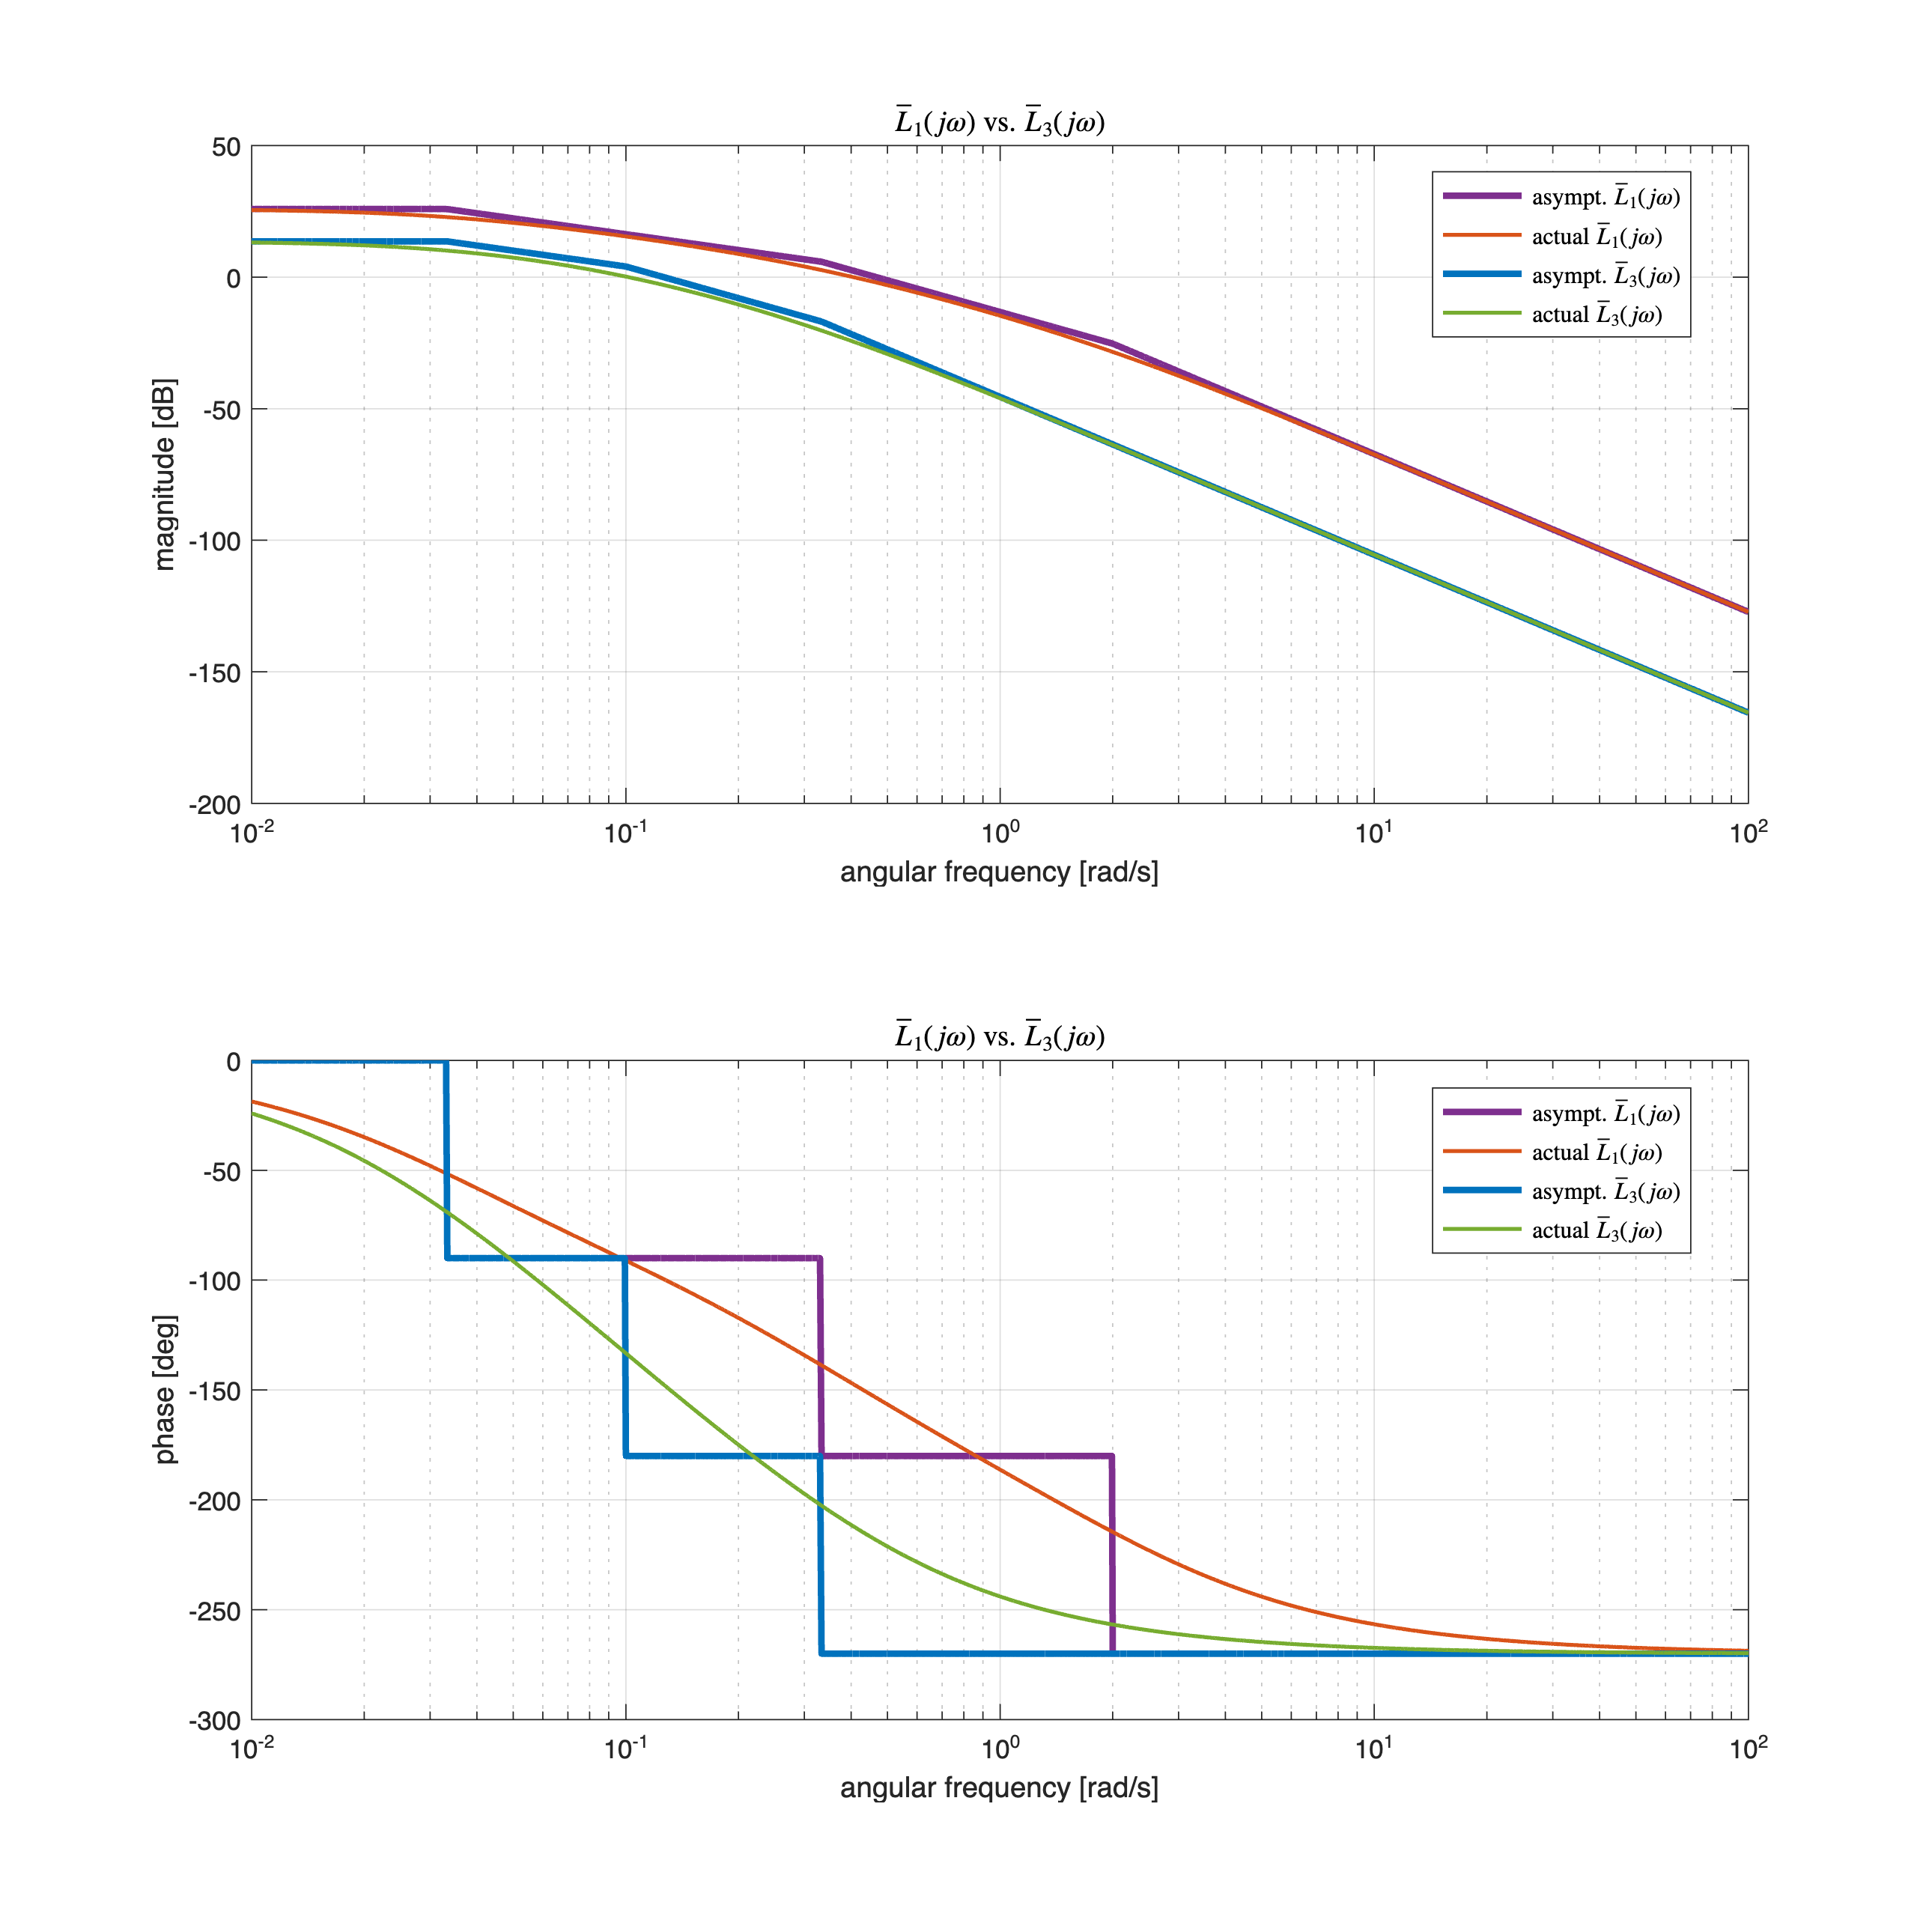

% ----- comparing the scenarios -----
hf10 = figure('Units','centimeters', 'Position',[0.1,0.1, 26, 26]);


omVALS = logspace(-2, 2, 1e5); % ang. freqs in [1/100; 100]
[hax5, hax6] = drawBodediagrams(L1s_A1_4, omVALS, Bcolors(3, :), 2.5, '-', ...
                       Bcolors(6, :), 1.5, '-', hf10); % assignment A1.2

drawBodediagrams(hatLs_A2_4, omVALS, Bcolors(1, :), 2.5, '-', ...
                       Bcolors(4, :), 1.5, '-', hf10);

title(hax5, '$\bar{L}_1(j \omega)$ vs. $\bar{L}_3(j \omega)$', 'Interpreter', 'latex');
title(hax6, '$\bar{L}_1(j \omega)$ vs. $\bar{L}_3(j \omega)$', 'Interpreter', 'latex');

legend(hax5,  'asympt. $\bar{L}_1(j \omega)$', 'actual $\bar{L}_1(j \omega)$', ...
             'asympt. $\bar{L}_3(j \omega)$', 'actual $\bar{L}_3(j \omega)$','Location', 'best', ...
             'Interpreter', 'latex');
legend(hax6,  'asympt. $\bar{L}_1(j \omega)$', 'actual $\bar{L}_1(j \omega)$', ...
             'asympt. $\bar{L}_3(j \omega)$', 'actual $\bar{L}_3(j \omega)$','Location', 'best', ...
             'Interpreter', 'latex');

% 1st scenario
[gainM_2loop, phaseM_2loop, OM_GM_2loop, OM_PM_2loop]= margin(L1s_A1_4)

gainM_2loop = 4.0001

phaseM_2loop = 32.7168

OM_GM_2loop = 0.8628

OM_PM_2loop = 0.4050


% 2nd scenario
[gainM_1loop, phaseM_1loop, OM_GM_1loop, OM_PM_1loop]= margin(hatLs_A2_4)

gainM_1loop = 4.0000

phaseM_1loop = 45.8954

OM_GM_1loop = 0.2186

OM_PM_1loop = 0.1014


% DC gain - 1st scenario
dcgain(L1s_A1_4)

ans = 19.5708


% DC gain - 2nd scenario
dcgain(hatLs_A2_4)

ans = 4.7667

% closed-loop step response - scenario 1
F1s = feedback(L1s_A1_4, 1, -1);
stepinfo(F1s, "SettlingTimeThreshold", 0.01)

ans = struct with fields:
         RiseTime: 2.8796
    TransientTime: 36.9733
     SettlingTime: 36.9733
      SettlingMin: 0.7909
      SettlingMax: 1.3368
        Overshoot: 40.5129
       Undershoot: 0
             Peak: 1.3368
         PeakTime: 7.3786



% closed-loop step response - scenario 1
hatFs = feedback(hatLs_A2_4, 1, -1);
stepinfo(hatFs, "SettlingTimeThreshold", 0.01)

ans = struct with fields:
         RiseTime: 11.2110
    TransientTime: 112.5913
     SettlingTime: 112.5913
      SettlingMin: 0.7288
      SettlingMax: 1.1023
        Overshoot: 33.3557
       Undershoot: 0
             Peak: 1.1023
         PeakTime: 28.4032


**Final remarks**:  The **second** **approach** (a single feedback loop) solution **performs** **worse** than the solution iin the former scenario (dual-loop control scheme):

- The gain margins are equal by design.

- In the latter case, the static gain is lower than in the former scenario: the steady-state error to a stepwise input will be larger in the second scenario than in the first one.

- Also, the crossover frequency is lower in the latter case: the closed-loop step response settling time is larger than the one in the former case (approximately three times the settling time obtained in the first scenario).

- As a trade-off to the faster closed-loop step response, the overshoot in the step response in the first scenario is higher than the overshoot in the latter scenario (approximately 7 % higher).

Removing the added folders to the Matlab path

% remove folders (and subfolders) to search path
rmpath(genpath('BodeDiagram/'))